# Analysis of Feedback Control Systems

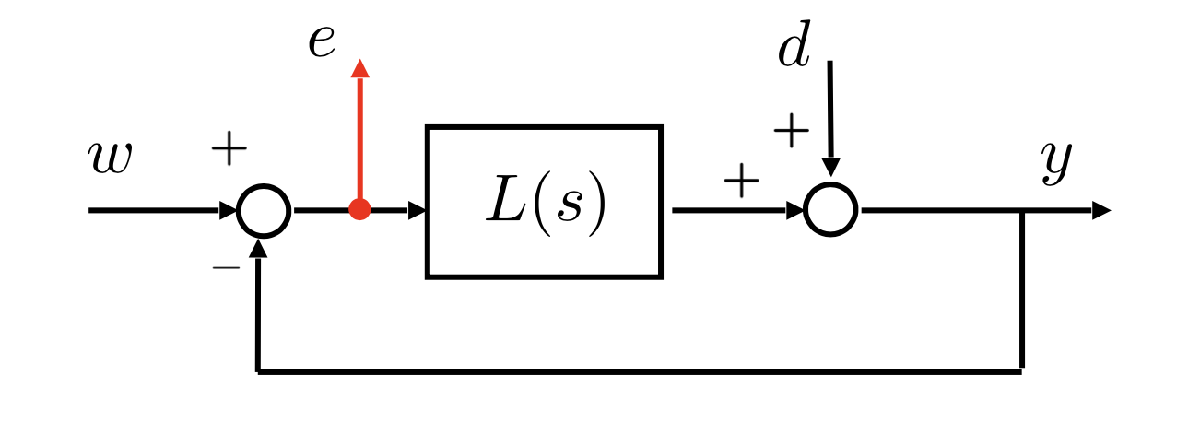

## Introduction

Consider the following open-loop transfer functions

clear
addpath(genpath('BodeDiagram/'))


s=tf('s');

L1s = 5/(1+s)^3;
L2s = 0.5*((1+5*s)^2/s)*(1/(1+s)^3);
L3s = 10*(s/(1+s/100))*(1/(1+s)^3);


### Gain and Phase Margins

How to compute the gain and the phase margins for each of the given transfer functions?

help margin

 margin - Gain margin, phase margin, and crossover frequencies
    This MATLAB function plots the Bode response of sys on the screen and
    indicates the gain and phase margins on the plot.

    Margin Plots
      margin(sys)
      margin(sys,w)

    Margin Values
      [Gm,Pm,Wcg,Wcp] = margin(sys)
      [Gm,Pm] = margin(sys,J1,...,JN)
      [Gm,Pm,Wcg,Wcp] = margin(sys,Focus=[fmin,fmax])
      [Gm,Pm,Wcg,Wcp] = margin(mag,phase,w)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      J - Indices of models in array whose gain and phase margins you want to extract
        positi

Thus, we have for `L1s`

[Gm1, Pm1, OMpi1, OMc1] = margin(L1s);
fprintf(['*** Transfer function L1s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n\r', ...
         'Ang. freq. OMpi [rad/s]: %.4f \r\n', ...
         'Phase margin [deg]: %.4f \n\r',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L1s ***\n\r'], ...
         Gm1, OMpi1, Pm1, OMc1);

*** Transfer function L1s ***


Gain Margin [dB]: 1.6002 

Ang. freq. OMpi [rad/s]: 1.7322 
Phase margin [deg]: 17.3704 

Crit. Ang. freq. OMc [rad/s]: 1.3870 


*** Transfer function L1s ***



Then for `L2s`:

[Gm2, Pm2, OMpi2, OMc2] = margin(L2s);
fprintf(['*** Transfer function L2s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n\r', ...
         'Ang. freq. OMpi [rad/s]: %.4f \r\n', ...
         'Phase margin [deg]: %.4f \n\r',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L2s ***\n\r'], ...
         Gm2, OMpi2, Pm2, OMc2);

*** Transfer function L2s ***


Gain Margin [dB]: Inf 

Ang. freq. OMpi [rad/s]: Inf 
Phase margin [deg]: 43.4166 

Crit. Ang. freq. OMc [rad/s]: 3.3181 


*** Transfer function L2s ***



And finally for `L3s`

[Gm3, Pm3, OMpi3, OMc3] = margin(L3s);
fprintf(['*** Transfer function L3s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n', ...
         'Ang. freq. OMpi [rad/s]: %.4f \n\r', ...
         'Phase margin [deg]: %.4f \r\n',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L3s ***\n\r'], ...
         Gm3, OMpi3, Pm3, OMc3);

*** Transfer function L3s ***


Gain Margin [dB]: 30.8747 
Ang. freq. OMpi [rad/s]: 17.3976 

Phase margin [deg]: 55.2790 
Crit. Ang. freq. OMc [rad/s]: 2.9073 


*** Transfer function L3s ***



### Issues with the tf( ) Command

Pay attention! If you use the following (correct) syntax, you will encounter possible numerical problems. In fact, the `tf()` command is **NOT** able to handle simplifications correctly.

F1sALT = L1s/(1+L1s)


F1sALT =
 
              5 s^3 + 15 s^2 + 15 s + 5
  -------------------------------------------------
  s^6 + 6 s^5 + 15 s^4 + 25 s^3 + 30 s^2 + 21 s + 6
 
Continuous-time transfer function.
Model Properties


zpk(F1sALT)


ans =
 
                5 (s+1)^3
  --------------------------------------
  (s+2.71) (s+1)^3 (s^2 + 0.29s + 2.214)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Excerpt from the [online documentation](https://it.mathworks.com/help/control/ref/tf.html?lang=en) regarding `tf( )`

**Limitations**

- Transfer function models are ill-suited for numerical computations. Once created, convert them to state-space form before combining them with other models or performing model transformations. You can then convert the resulting models back to transfer function form for inspection purposes.

#### Proposed Solution

To avoid these problems, it is preferable to use the `feedback()` command to obtain the closed-loop transfer function from the open-loop one.  

F1s = feedback(L1s, 1, -1)


F1s =
 
            5
  ---------------------
  s^3 + 3 s^2 + 3 s + 6
 
Continuous-time transfer function.
Model Properties


## The Complementary Sensitivity Function

Given the transfer functions $L_1(s), \, L_2(s)$ and $L_3(s)$, the corresponding closed-loop functions $F(s)$ are


$$F(s) = \frac{L(s)}{1+L(s)}$$


F1s = feedback(L1s, 1, -1)


F1s =
 
            5
  ---------------------
  s^3 + 3 s^2 + 3 s + 6
 
Continuous-time transfer function.
Model Properties



F2s = feedback(L2s, 1, -1)


F2s =
 
         12.5 s^2 + 5 s + 0.5
  ----------------------------------
  s^4 + 3 s^3 + 15.5 s^2 + 6 s + 0.5
 
Continuous-time transfer function.
Model Properties



F3s = feedback(L3s, 1, -1)


F3s =
 
                  1000 s
  --------------------------------------
  s^4 + 103 s^3 + 303 s^2 + 1301 s + 100
 
Continuous-time transfer function.
Model Properties


### Static Gain and Pole-Zero Analysis

Remember:

zero(L1s)


ans =

  0×1 empty double column vector



pole(L1s)

ans =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i


zero(L2s)

ans =   -0.2000 + 0.0000i
  -0.2000 - 0.0000i


pole(L2s)

ans =    0.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i


pole(L3s)

ans = 1.0e+02 *

  -1.0000 + 0.0000i
  -0.0100 + 0.0000i
  -0.0100 + 0.0000i
  -0.0100 - 0.0000i


zero(L3s)

ans = 0

#### Static Gain


dcF10 = dcgain(F1s)

dcF10 = 0.8333


dcF20 = dcgain(F2s)

dcF20 = 1


dcF30 = dcgain(F3s)

dcF30 = 0

#### Poles & Zeros 

zpk(L1s)


ans =
 
     5
  -------
  (s+1)^3
 
Continuous-time zero/pole/gain model.
Model Properties



zpk(F1s)


ans =
 
                5
  ------------------------------
  (s+2.71) (s^2 + 0.29s + 2.214)
 
Continuous-time zero/pole/gain model.
Model Properties


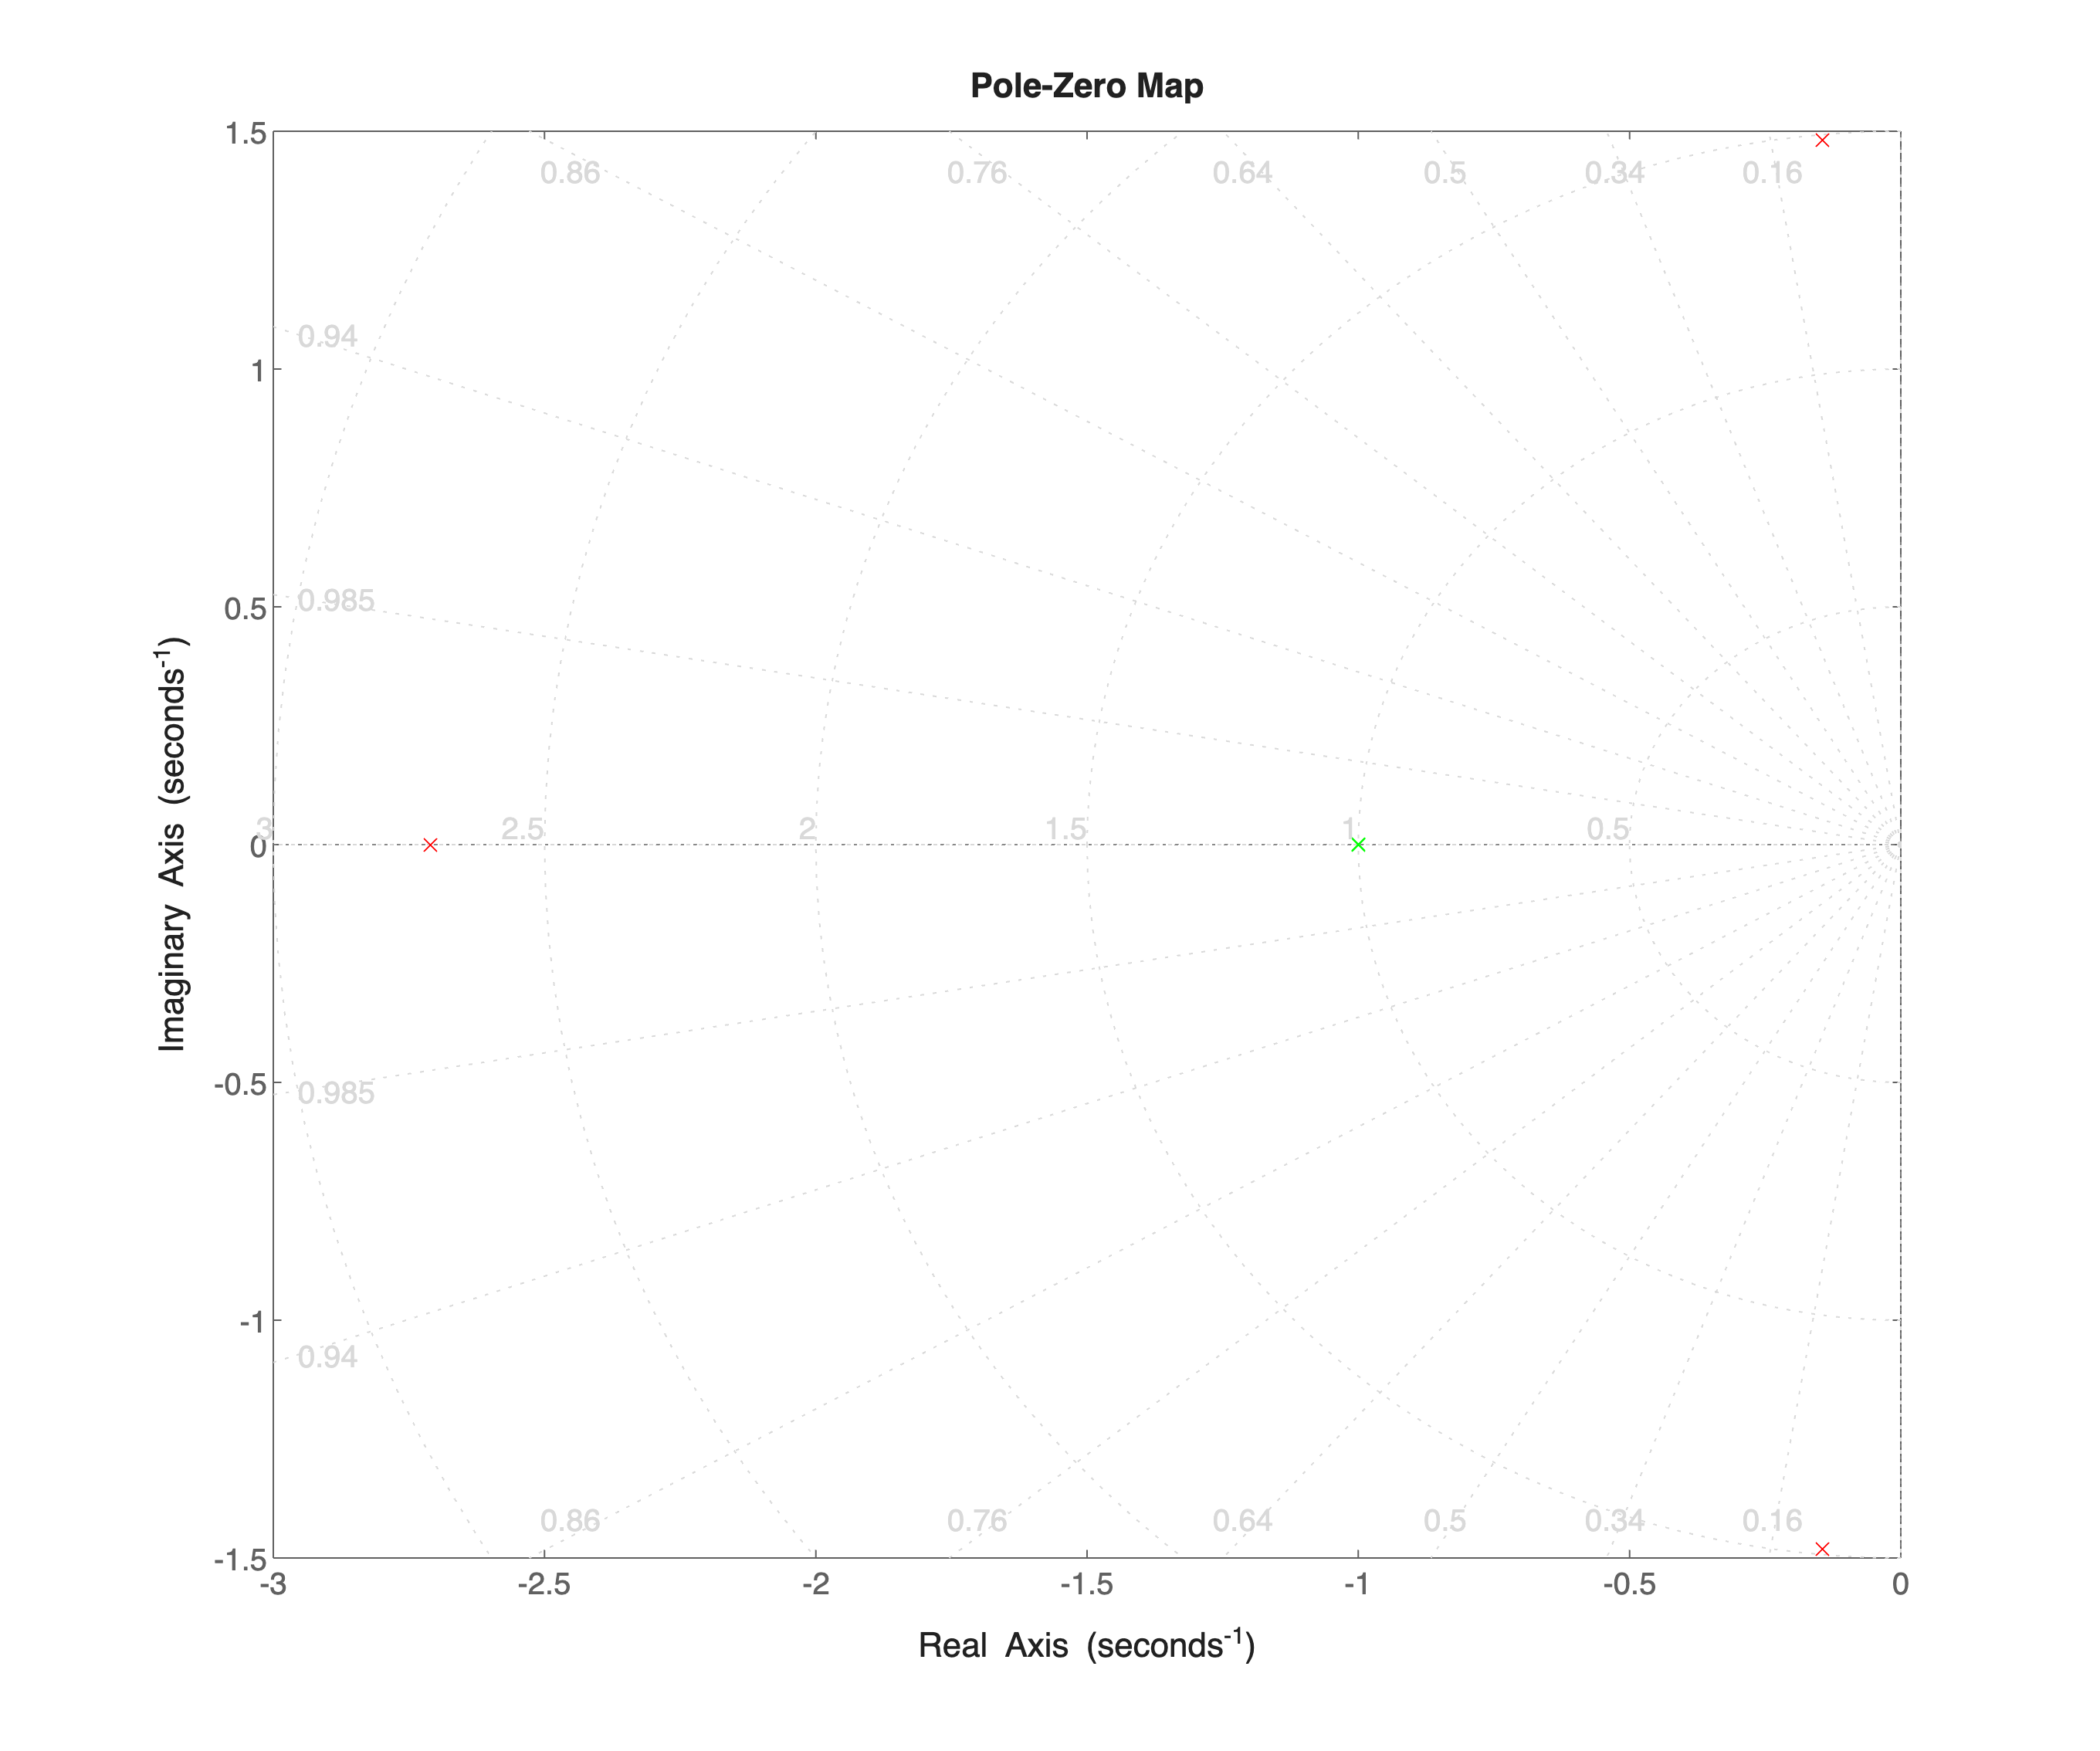



figure('Units','centimeters', 'Position',[0.1, 0.1, 24, 20]);
pzplot(F1s, 'r', L1s, 'g'); 
grid on


% trick based on
% https://it.mathworks.com/matlabcentral/answers/276605-change-pzplot-marker-size
%
% 
% a = findobj(gca,'type','line');
% for i = 1:length(a)
%     set(a(i),'markersize',14); % change marker size
%     set(a(i), 'linewidth',2);  % change linewidth
% end

% legend(gca, {'F1s', 'L1s'}, ....
%      'fontsize', 14, 'Location', 'best');



zpk(L2s)


ans =
 
  12.5 (s+0.2)^2
  --------------
    s (s+1)^3
 
Continuous-time zero/pole/gain model.
Model Properties



zpk(F2s)


ans =
 
                12.5 (s+0.2)^2
  ------------------------------------------
  (s+0.2911) (s+0.1193) (s^2 + 2.59s + 14.4)
 
Continuous-time zero/pole/gain model.
Model Properties


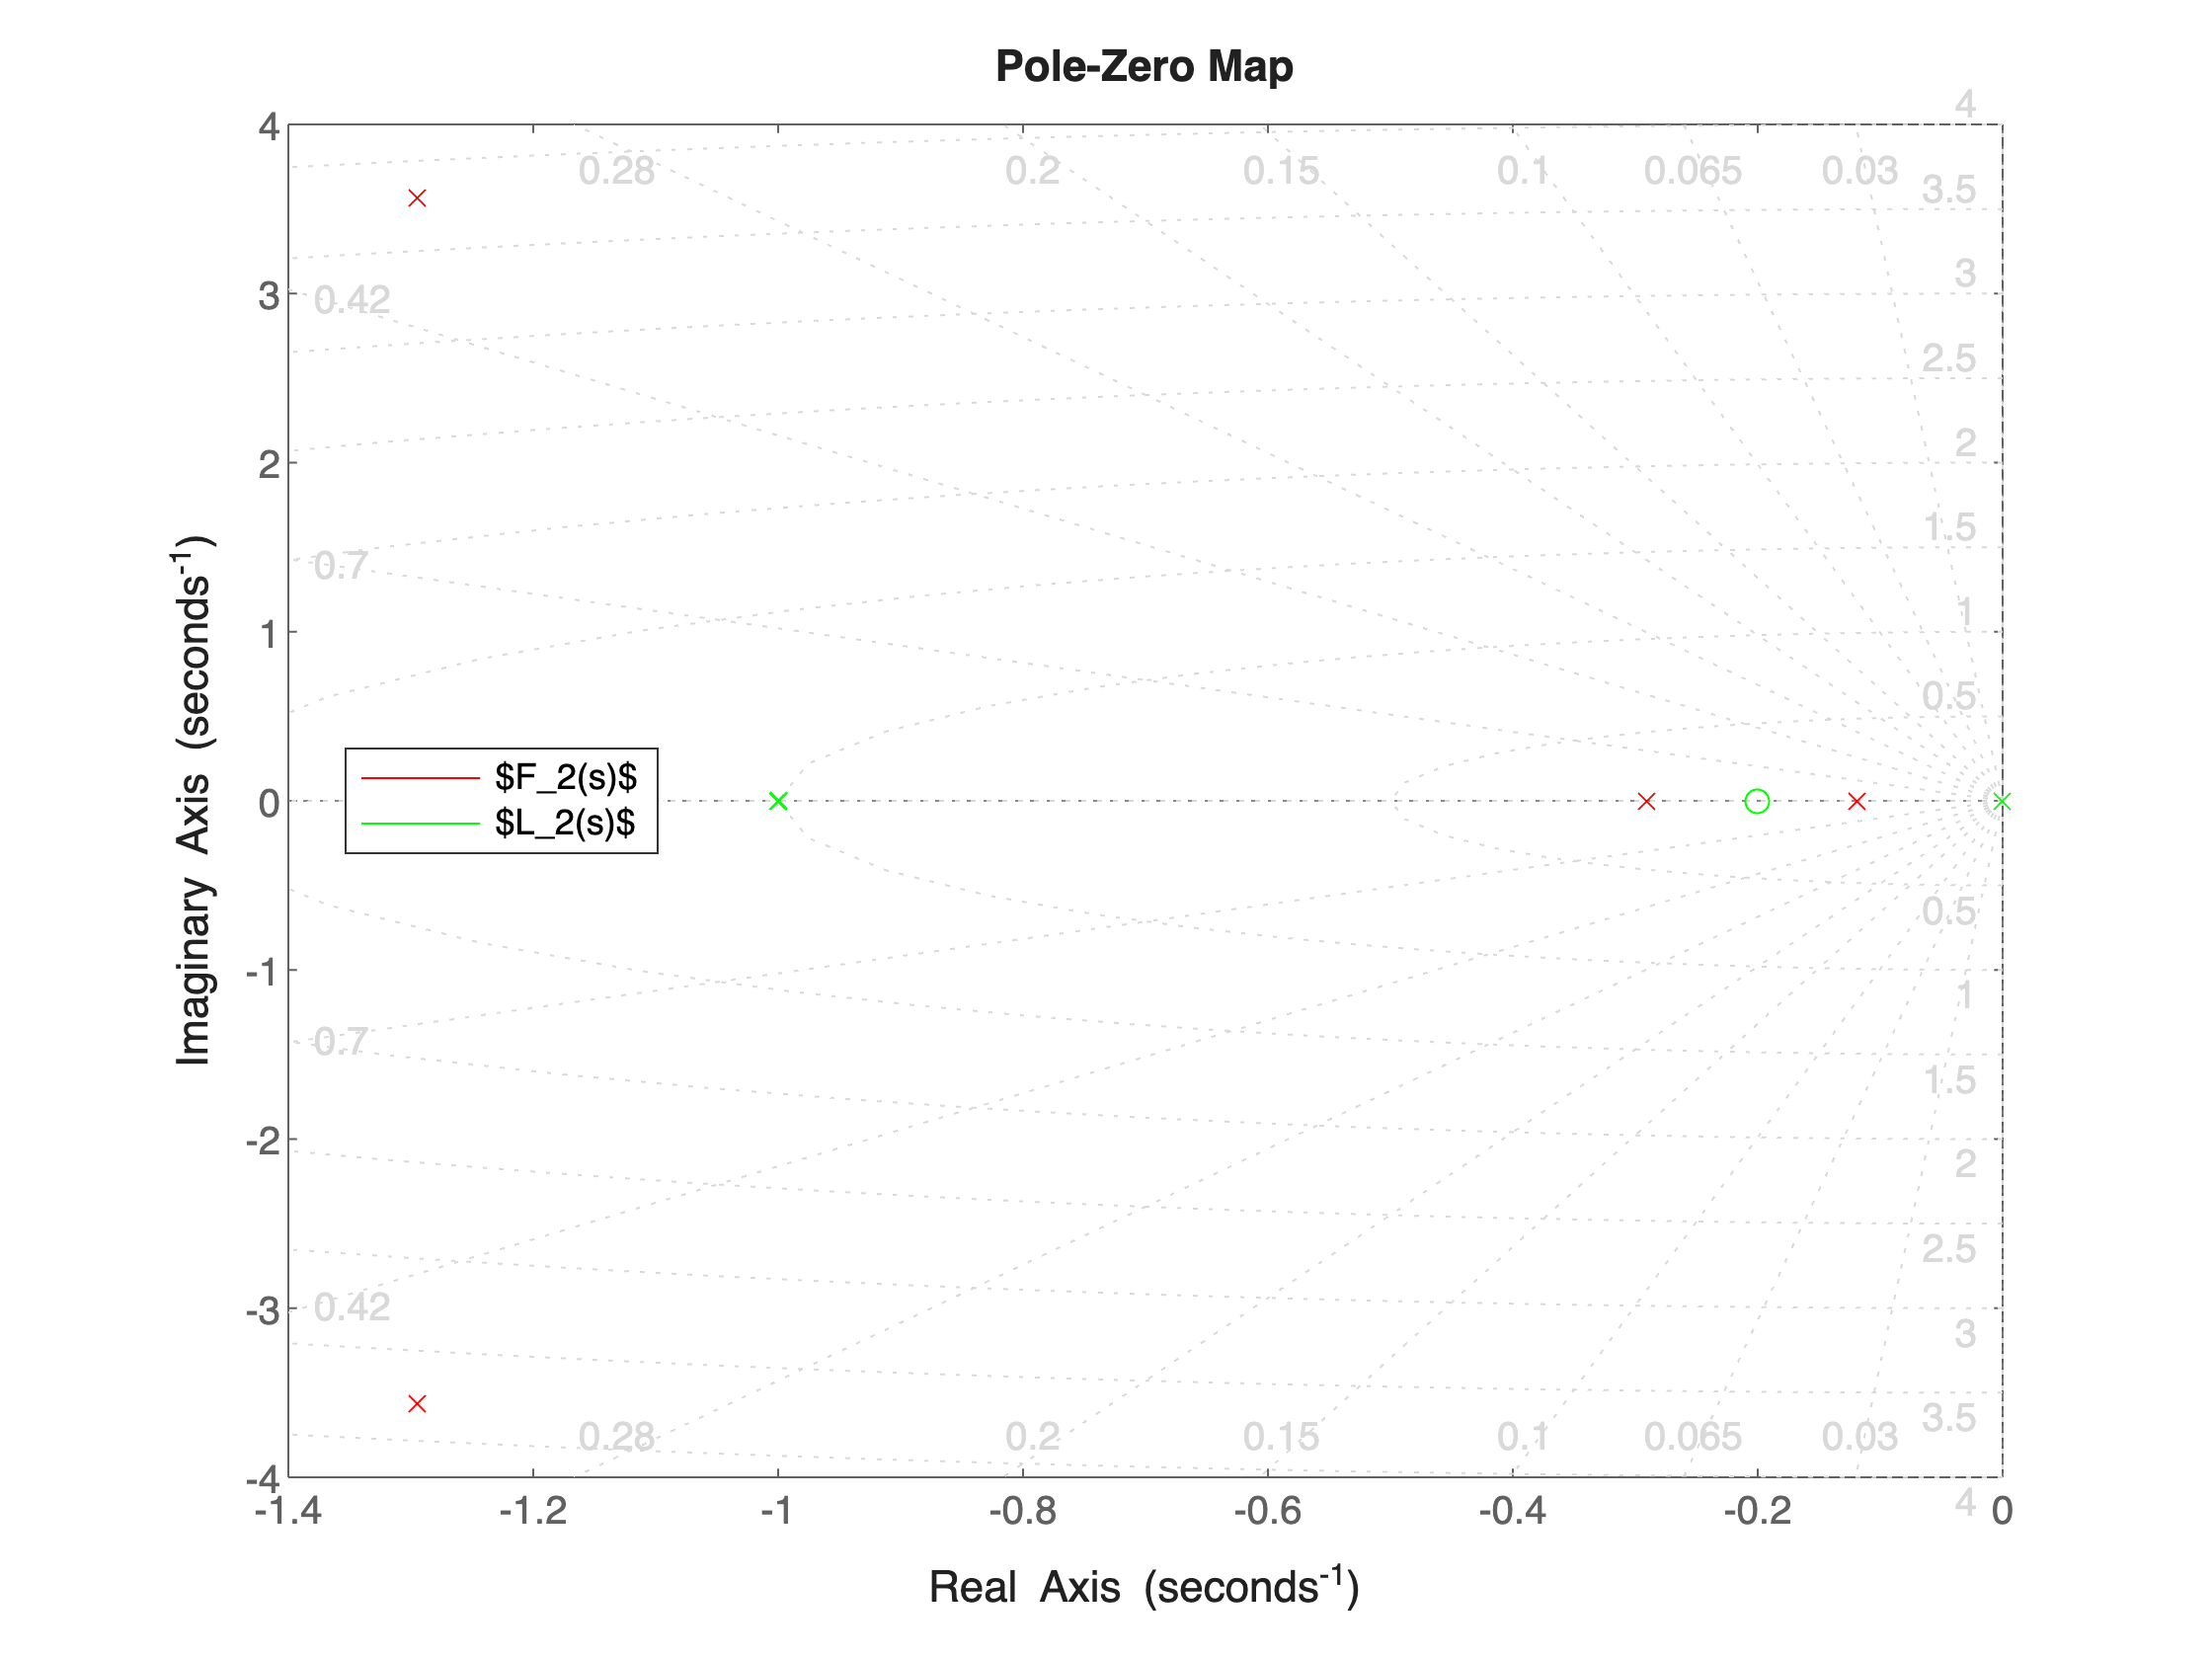



figure;
pzplot(F2s, 'r', L2s, 'g'); 
grid on

% trick based on
% https://it.mathworks.com/matlabcentral/answers/276605-change-pzplot-marker-size
%

a = findobj(gca,'type','line');
for i = 1:length(a)
    set(a(i),'markersize',14); % change marker size
    set(a(i), 'linewidth',2);  % change linewidth
end

legend(gca,'$F_2(s)$', '$L_2(s)$',....
    'Interpreter', 'latex', 'fontsize', 14, 'Location', 'best');

zpk(L3s)


ans =
 
      1000 s
  ---------------
  (s+100) (s+1)^3
 
Continuous-time zero/pole/gain model.
Model Properties



zpk(F3s)


ans =
 
                     1000 s
  --------------------------------------------
  (s+100.1) (s+0.07825) (s^2 + 2.819s + 12.77)
 
Continuous-time zero/pole/gain model.
Model Properties


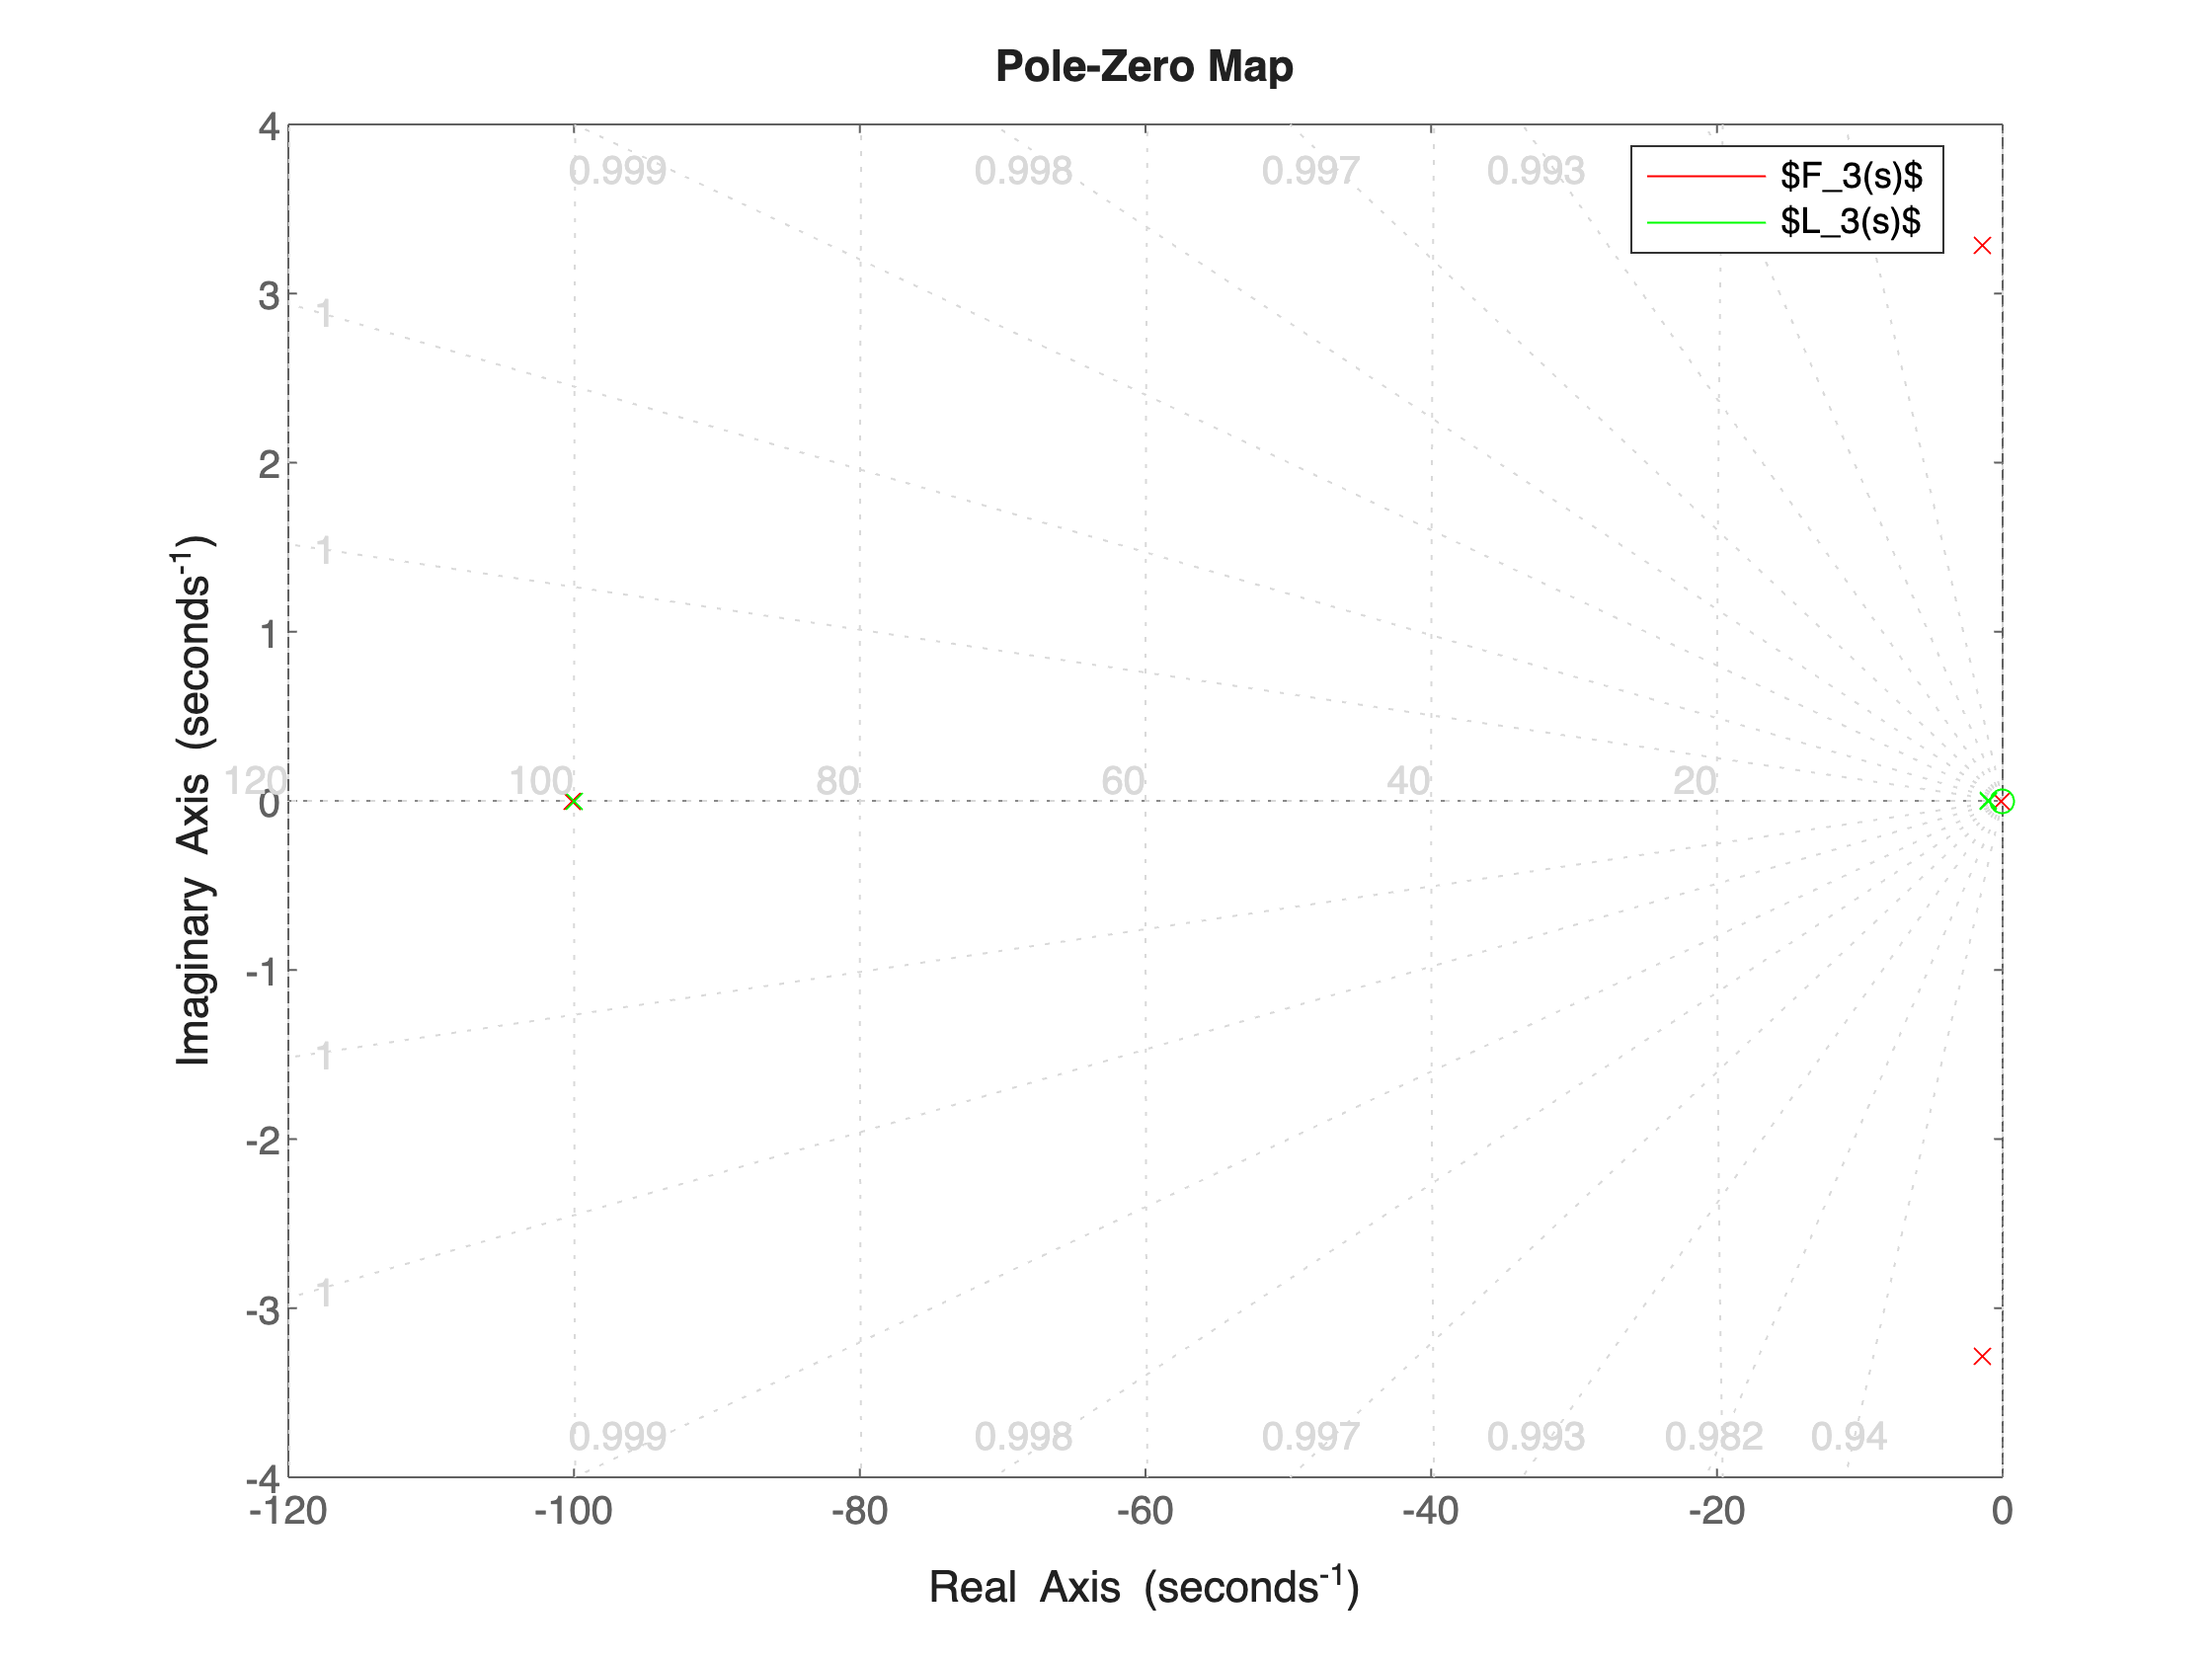



figure;
pzplot(F3s, 'r', L3s, 'g'); 
grid on

a = findobj(gca,'type','line');
for i = 1:length(a)
    set(a(i),'markersize',14); % change marker size
    set(a(i), 'linewidth',2);  % change linewidth
end

legend(gca, '$F_3(s)$', '$L_3(s)$',....
    'Interpreter', 'latex', 'fontsize', 14, 'Location', 'best');

### Frequency Response Analysis

Consider


$$L_4(s) = \mu_L \, \frac{\left(1+\frac{s}{50}\right)}{ \left(1+\frac{s}{2}\right)\,\left(1+0.8\, s +\frac{s^2}{4}\right)}}$$


with $\mu_L = 1.2,\, 5.45$

Let's compare the frequency response of the open-loop transfer function $L_4(s)$ and that of the closed-loop transfer function $F_4(s)$.

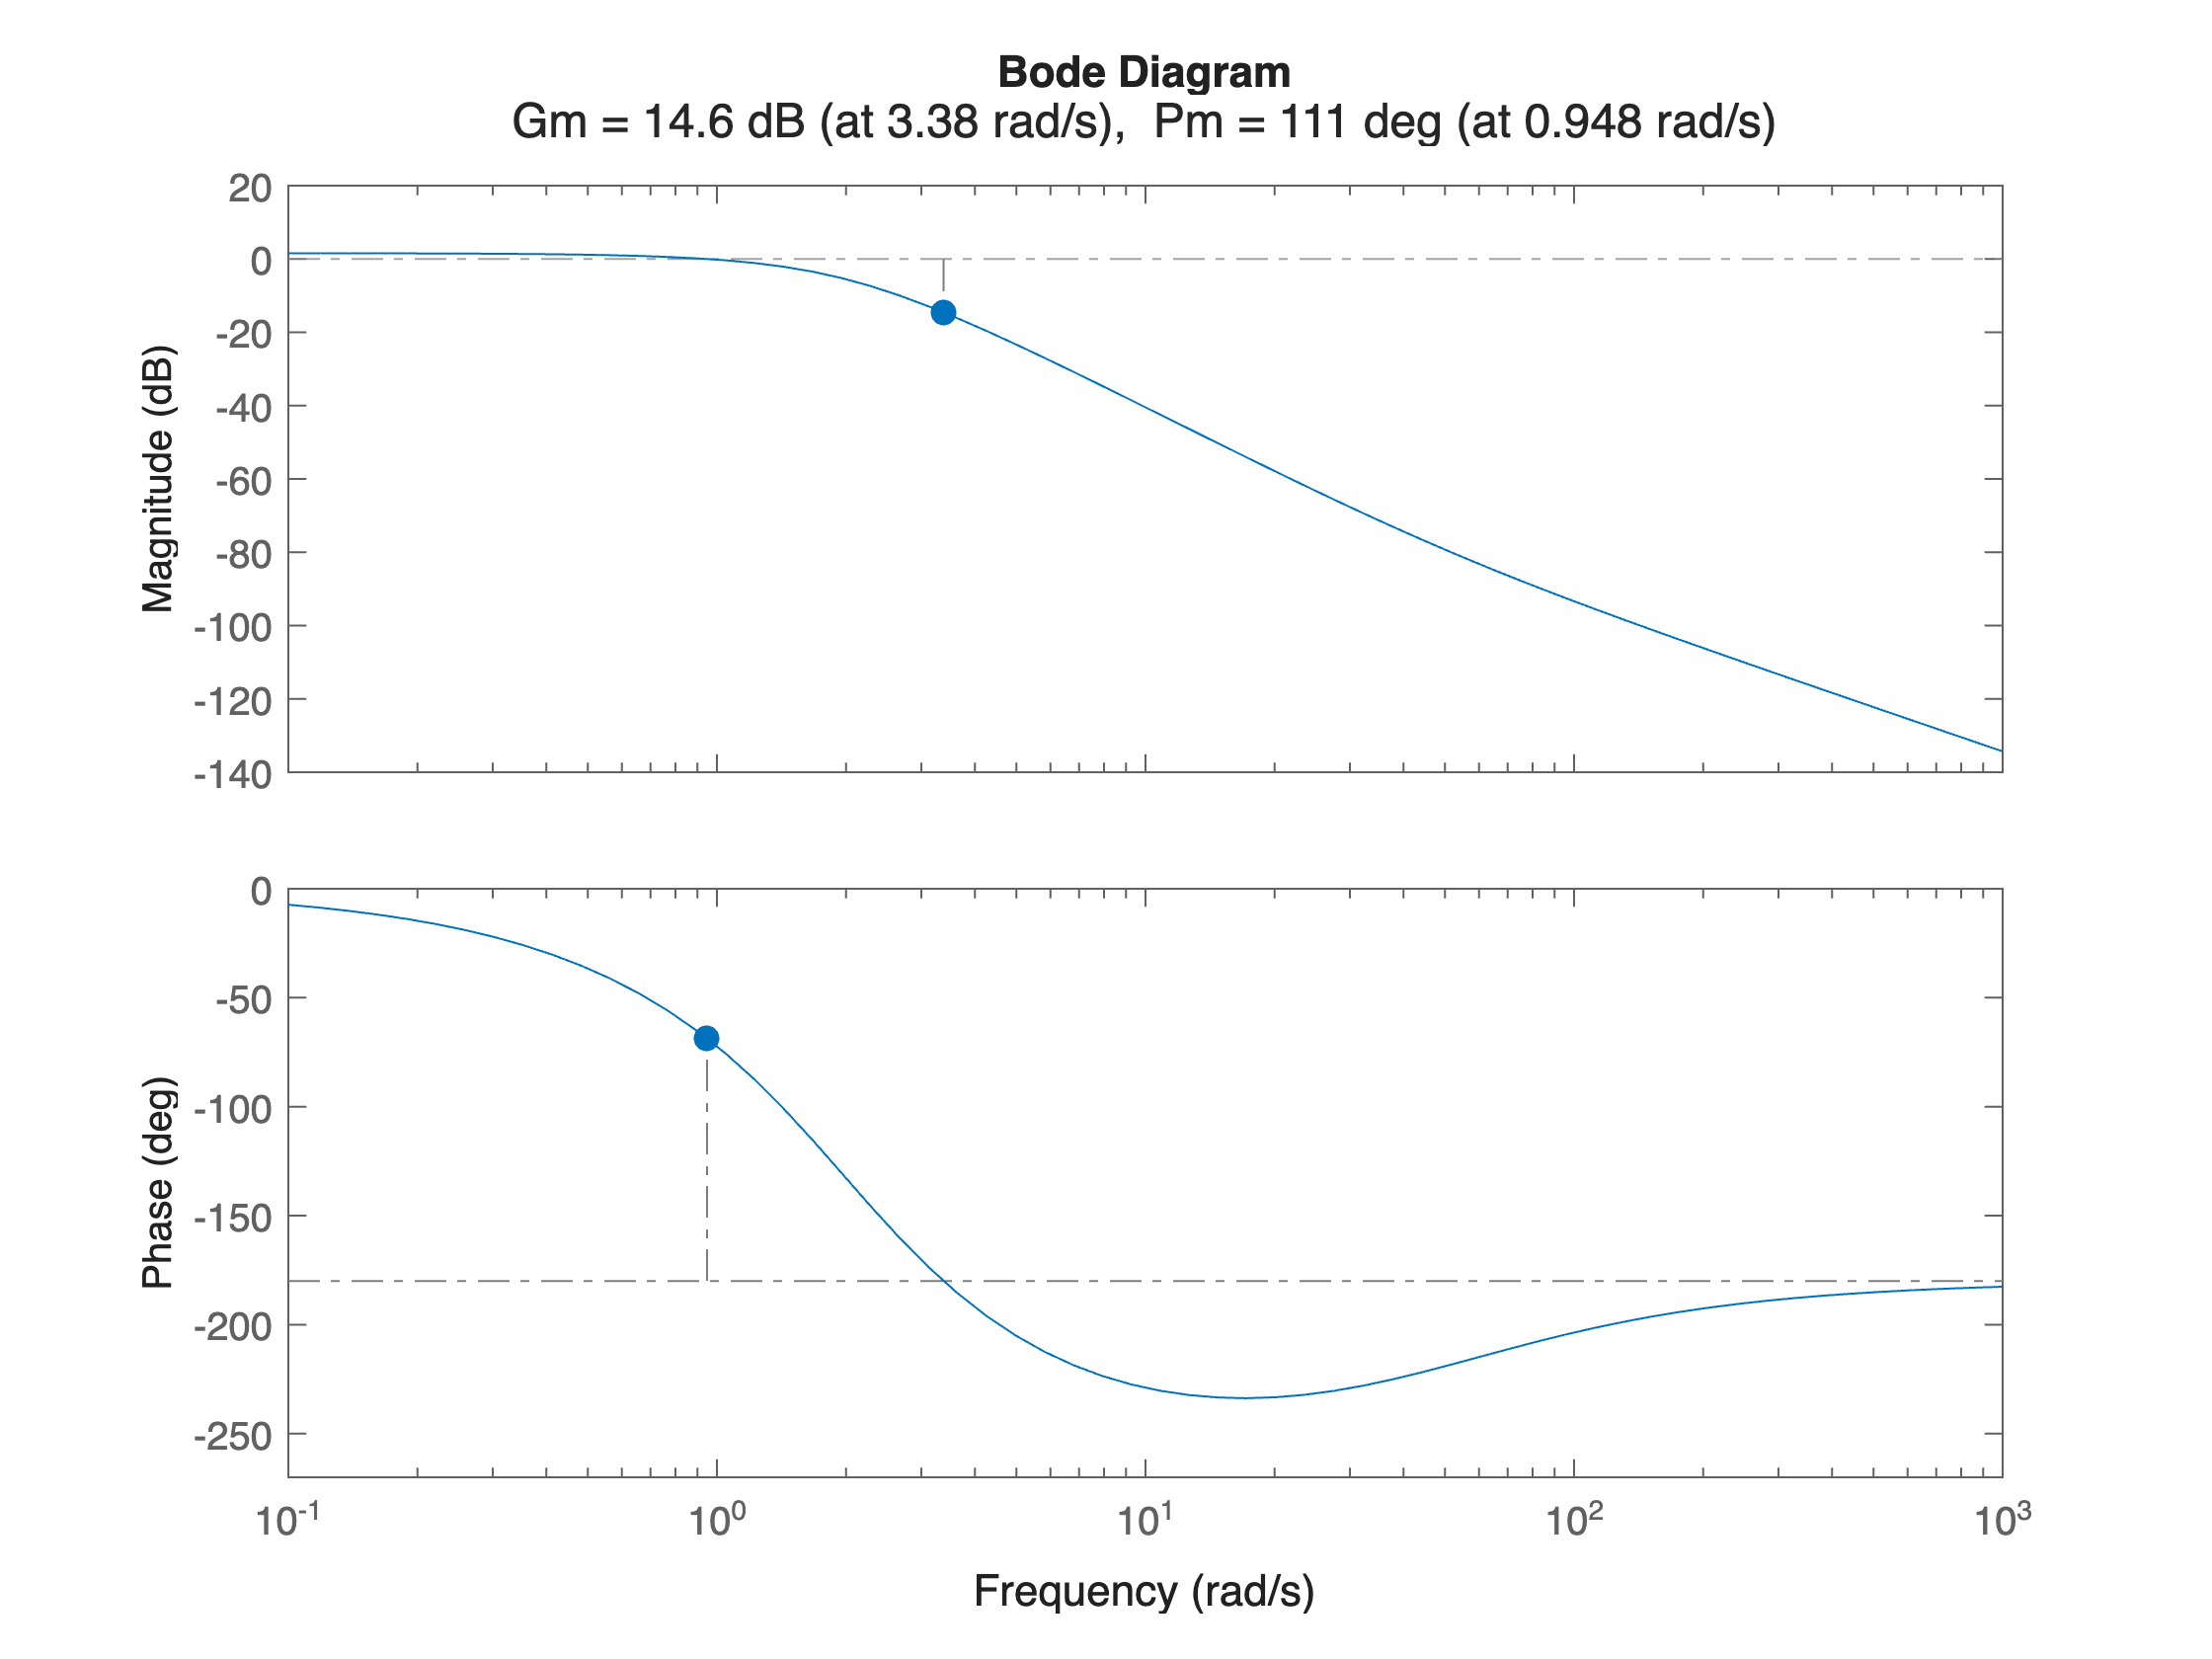

muL4default = 1.20;
muL4 = 1.2; % try muL4 = 5.45
L4s = muL4*(1+s/50)/((1+s/2)*(1+0.8*s+s^2/4));

F4s = feedback(L4s,1,-1);

figure;margin(L4s)

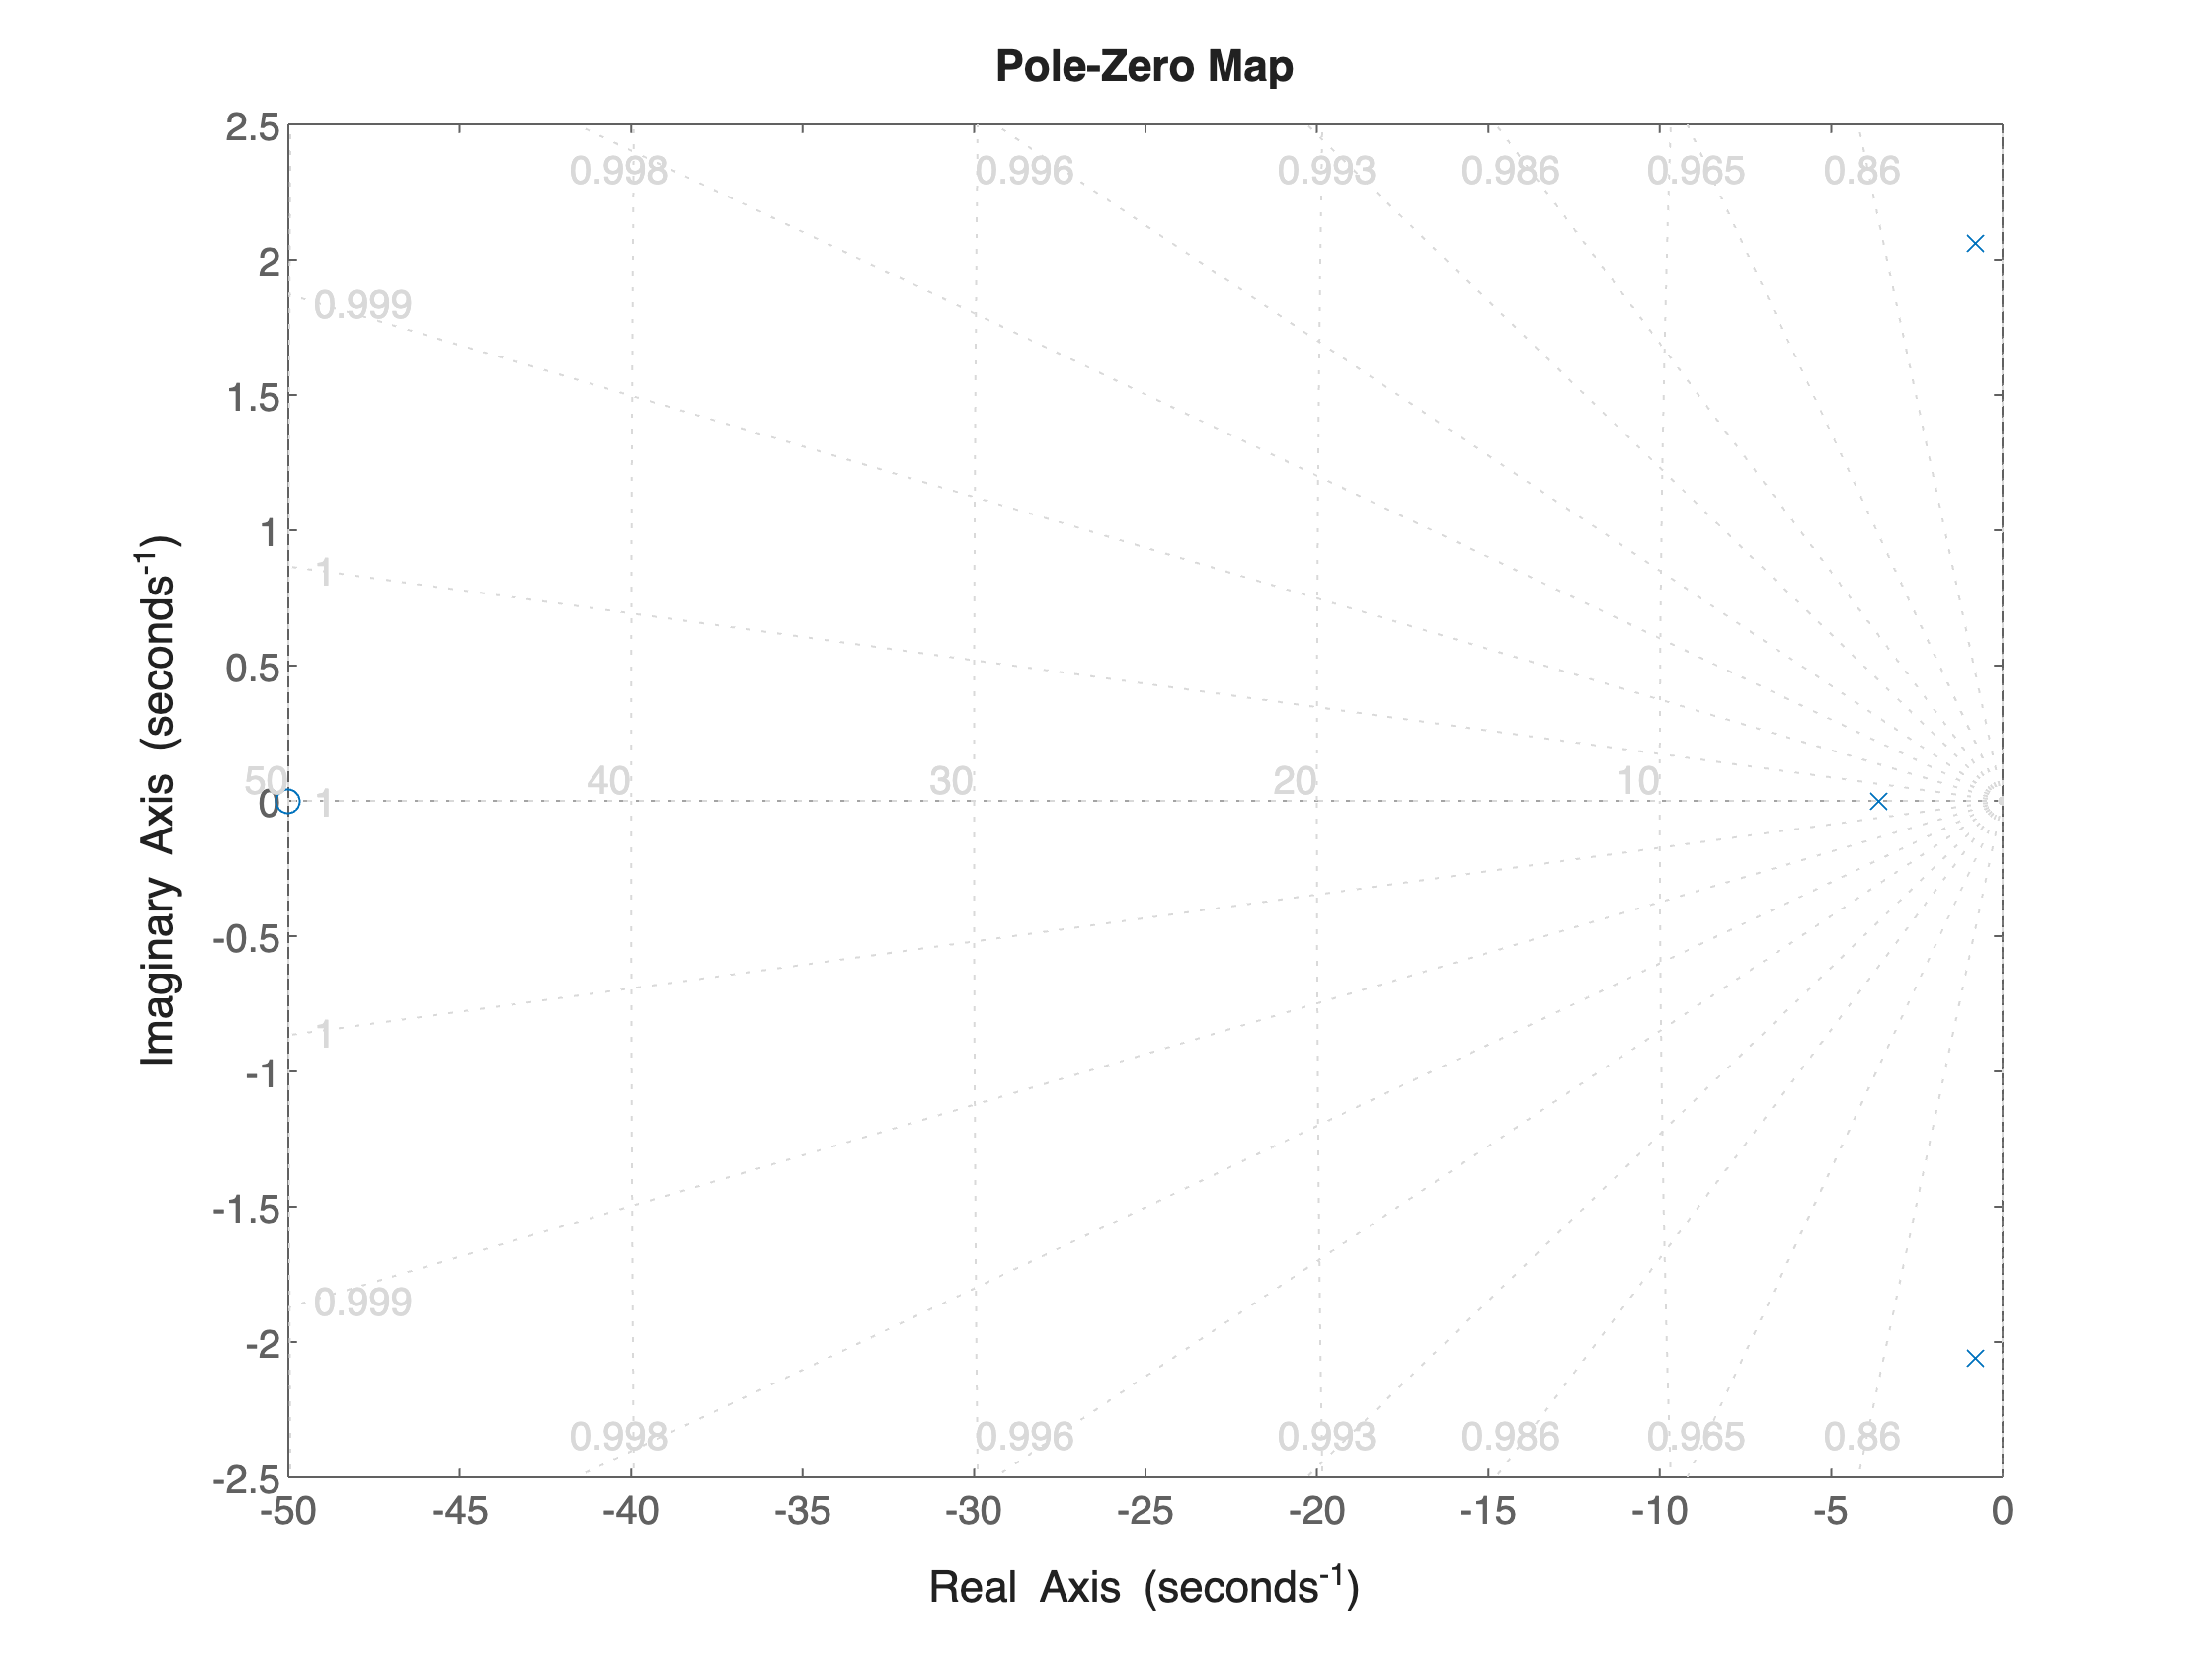


figure;pzmap(F4s);
grid on


a = findobj(gca,'type','line');
for i = 1:length(a)
    set(a(i),'markersize',14); % change marker size
    set(a(i), 'linewidth',2);  % change linewidth
end
pole(F4s)

ans =   -3.6169 + 0.0000i
  -0.7916 + 2.0590i
  -0.7916 - 2.0590i



hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams



drawBodediagrams(L4s, omVALS, asBcolor, 2.5, '-', ...
               Bcolors(1, :), 1.5, '-', hf);

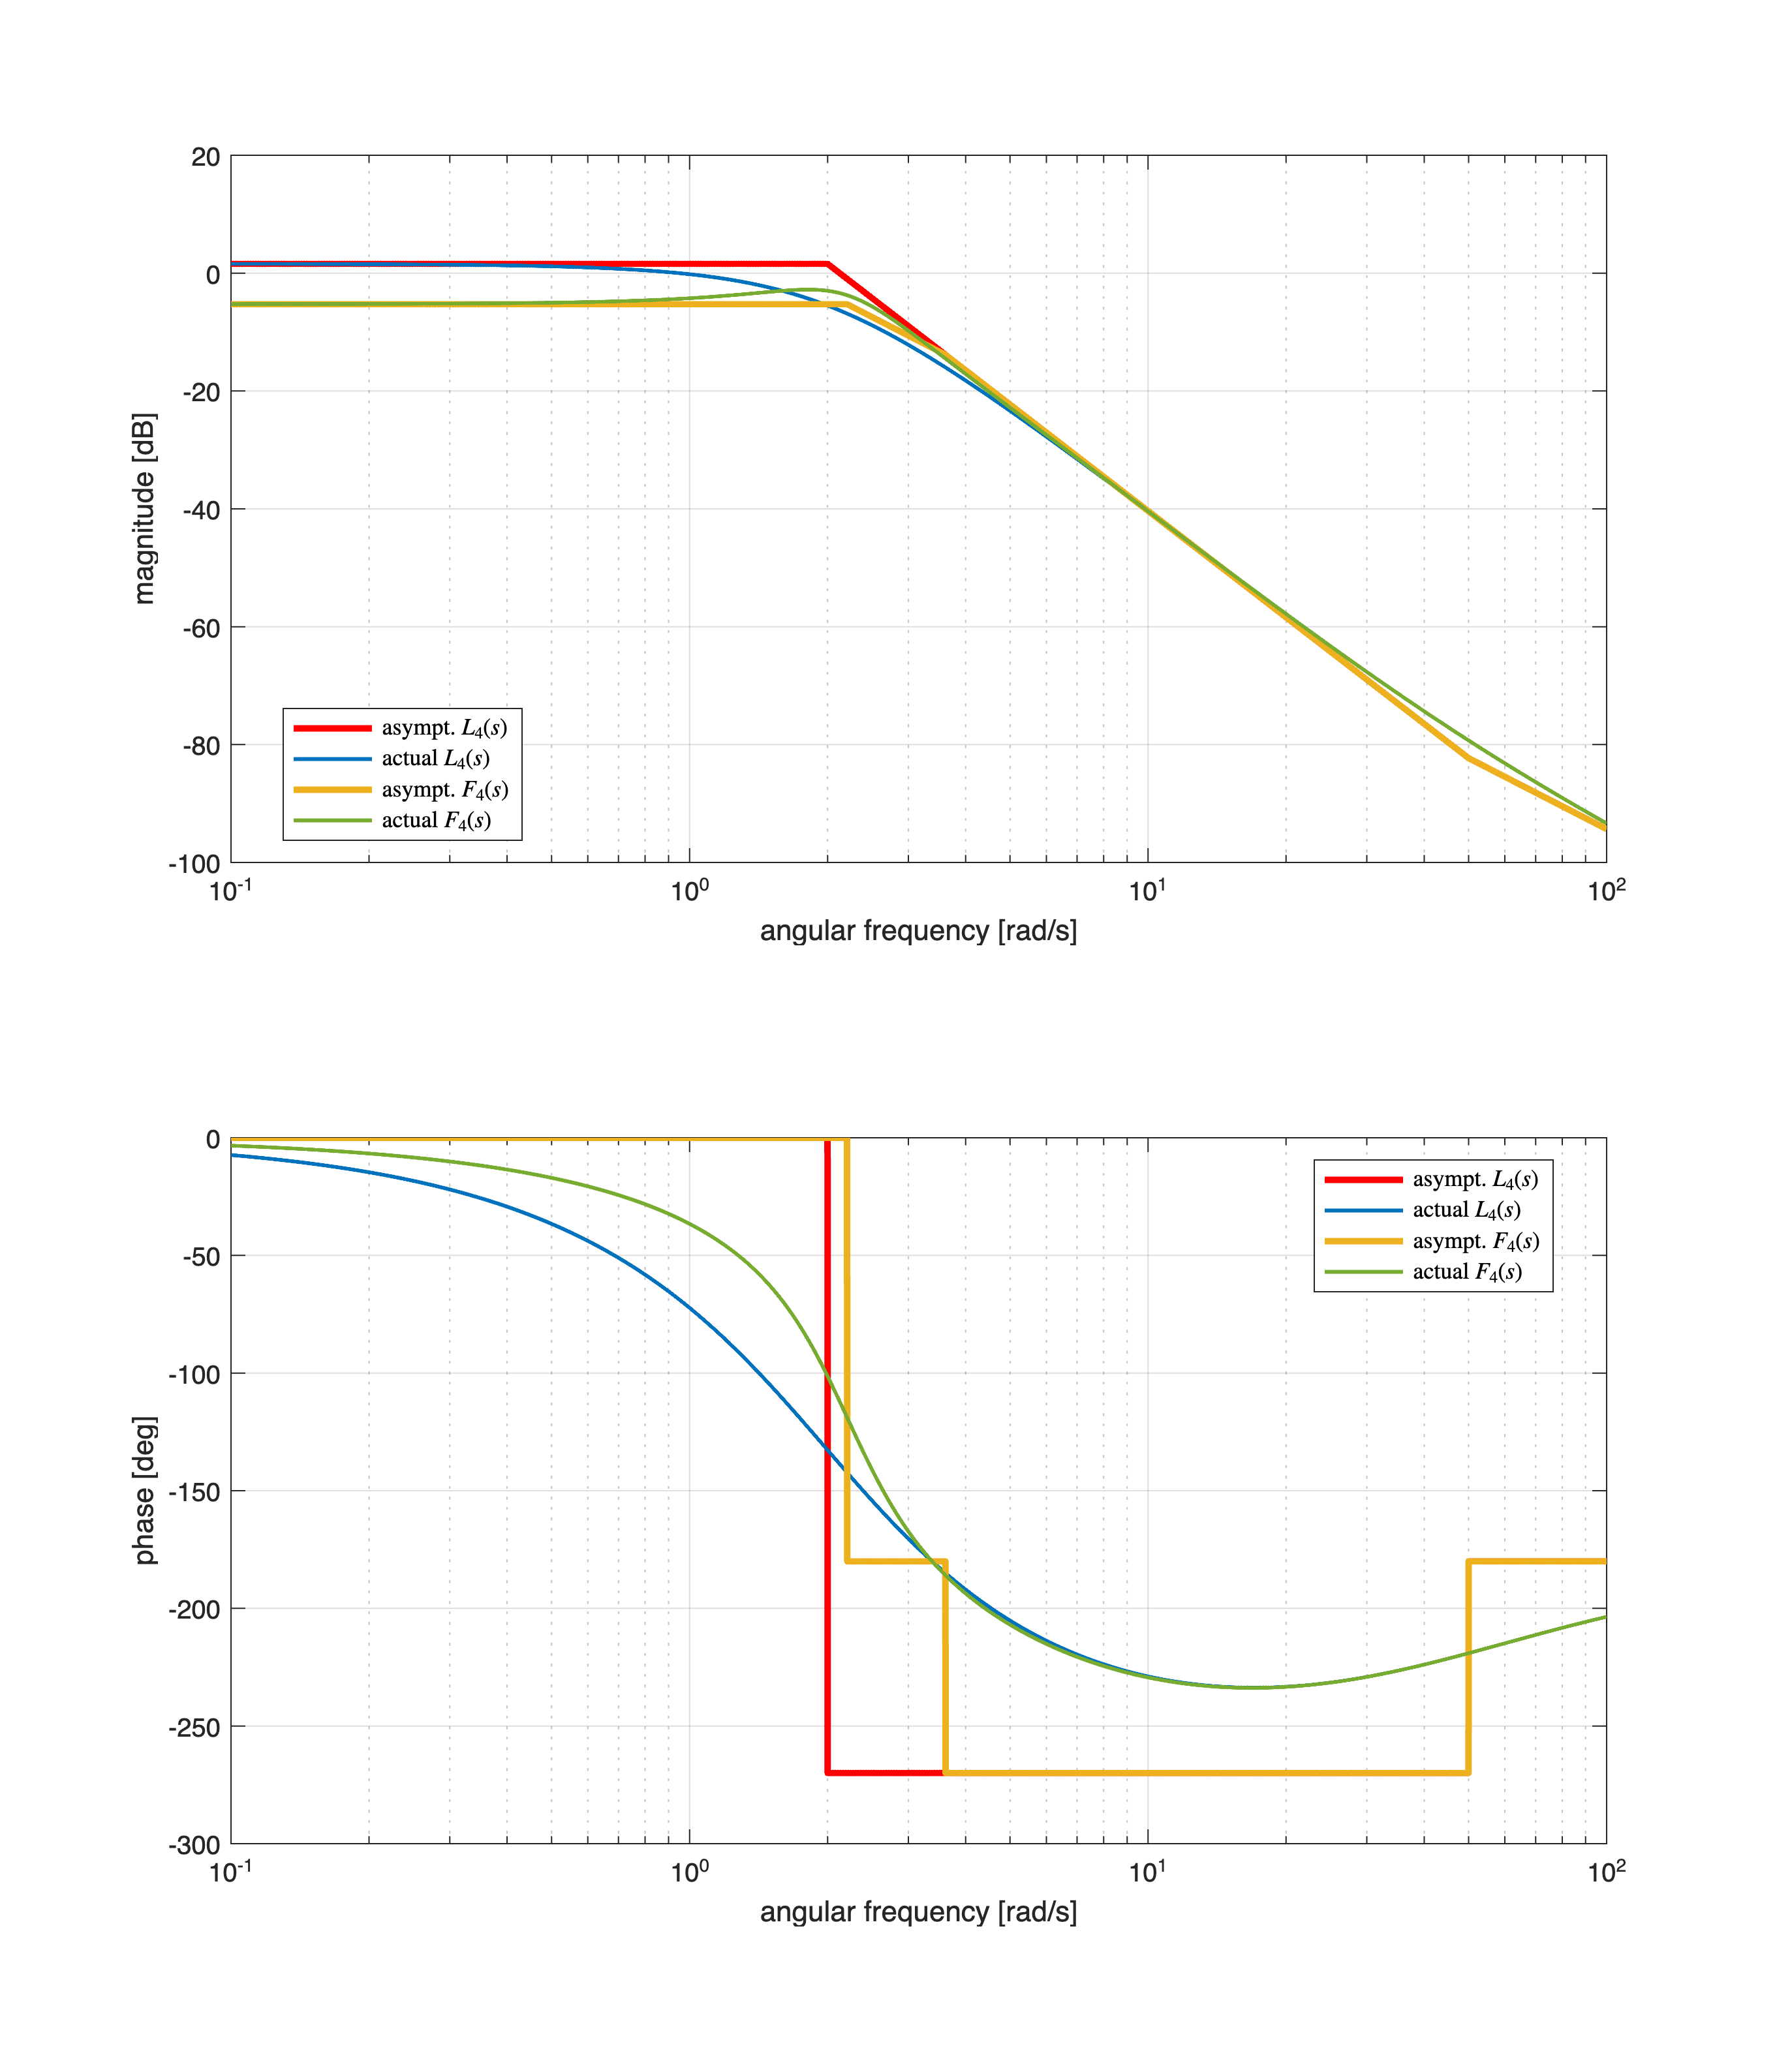

[hax1, hax2] = drawBodediagrams(F4s, omVALS, Bcolors(2, :), 2.5, '-', ...
               Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L_{4}(s)$', 'actual $L_{4}(s)$', ...
             'asympt. $F_{4}(s)$', 'actual $F_{4}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');
legend(hax2, 'asympt. $L_{4}(s)$', 'actual $L_{4}(s)$', ...
             'asympt. $F_{4}(s)$', 'actual $F_{4}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');

### More Examples

[Gm1, Pm1, OMpi1, OMc1] = margin(L1s);
fprintf(['*** Transfer function L1s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n\r', ...
         'Ang. freq. OMpi [rad/s]: %.4f \r\n', ...
         'Phase margin [deg]: %.4f \n\r',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L1s ***\n\r'], ...
         Gm1, OMpi1, Pm1, OMc1);

*** Transfer function L1s ***


Gain Margin [dB]: 1.6002 

Ang. freq. OMpi [rad/s]: 1.7322 
Phase margin [deg]: 17.3704 

Crit. Ang. freq. OMc [rad/s]: 1.3870 


*** Transfer function L1s ***



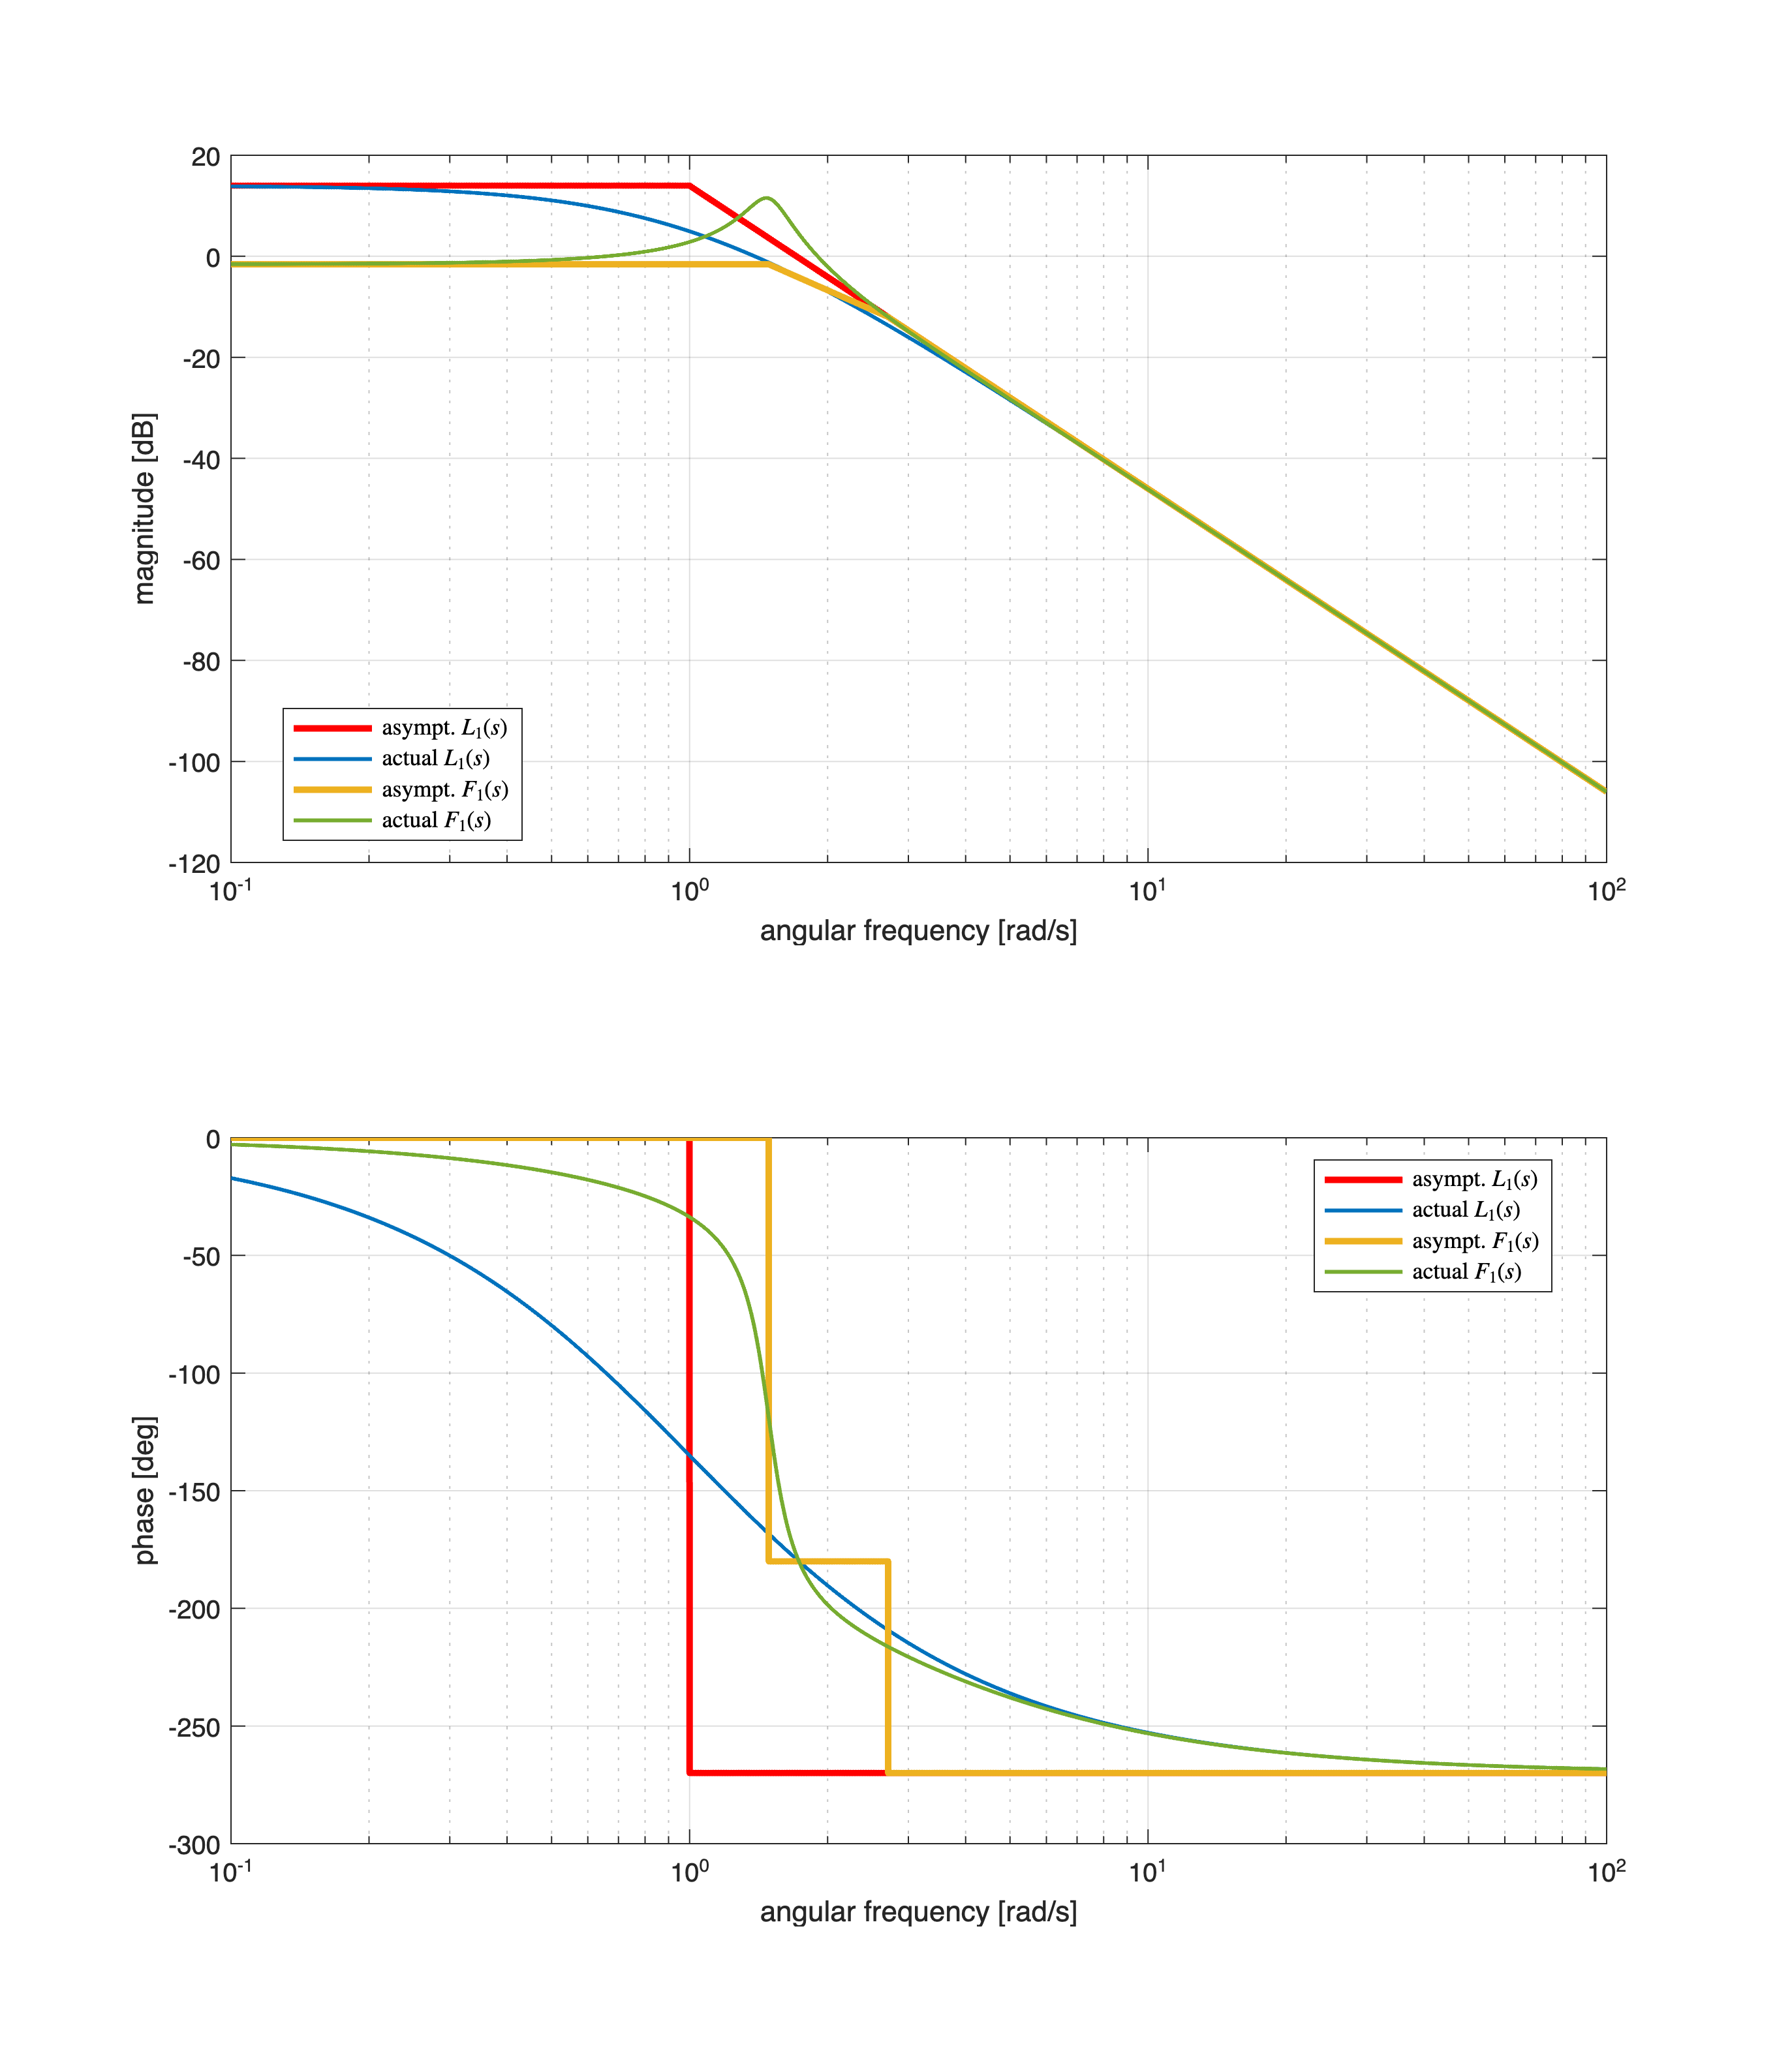


hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams



drawBodediagrams(L1s, omVALS, asBcolor, 2.5, '-', ...
               Bcolors(1, :), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(F1s, omVALS, Bcolors(2, :), 2.5, '-', ...
               Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L_{1}(s)$', 'actual $L_{1}(s)$', ...
             'asympt. $F_{1}(s)$', 'actual $F_{1}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');
legend(hax2, 'asympt. $L_{1}(s)$', 'actual $L_{1}(s)$', ...
             'asympt. $F_{1}(s)$', 'actual $F_{1}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');

[Gm2, Pm2, OMpi2, OMc2] = margin(L2s);
fprintf(['*** Transfer function L2s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n\r', ...
         'Ang. freq. OMpi [rad/s]: %.4f \r\n', ...
         'Phase margin [deg]: %.4f \n\r',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L2s ***\n\r'], ...
         Gm2, OMpi2, Pm2, OMc2);

*** Transfer function L2s ***


Gain Margin [dB]: Inf 

Ang. freq. OMpi [rad/s]: Inf 
Phase margin [deg]: 43.4166 

Crit. Ang. freq. OMc [rad/s]: 3.3181 


*** Transfer function L2s ***



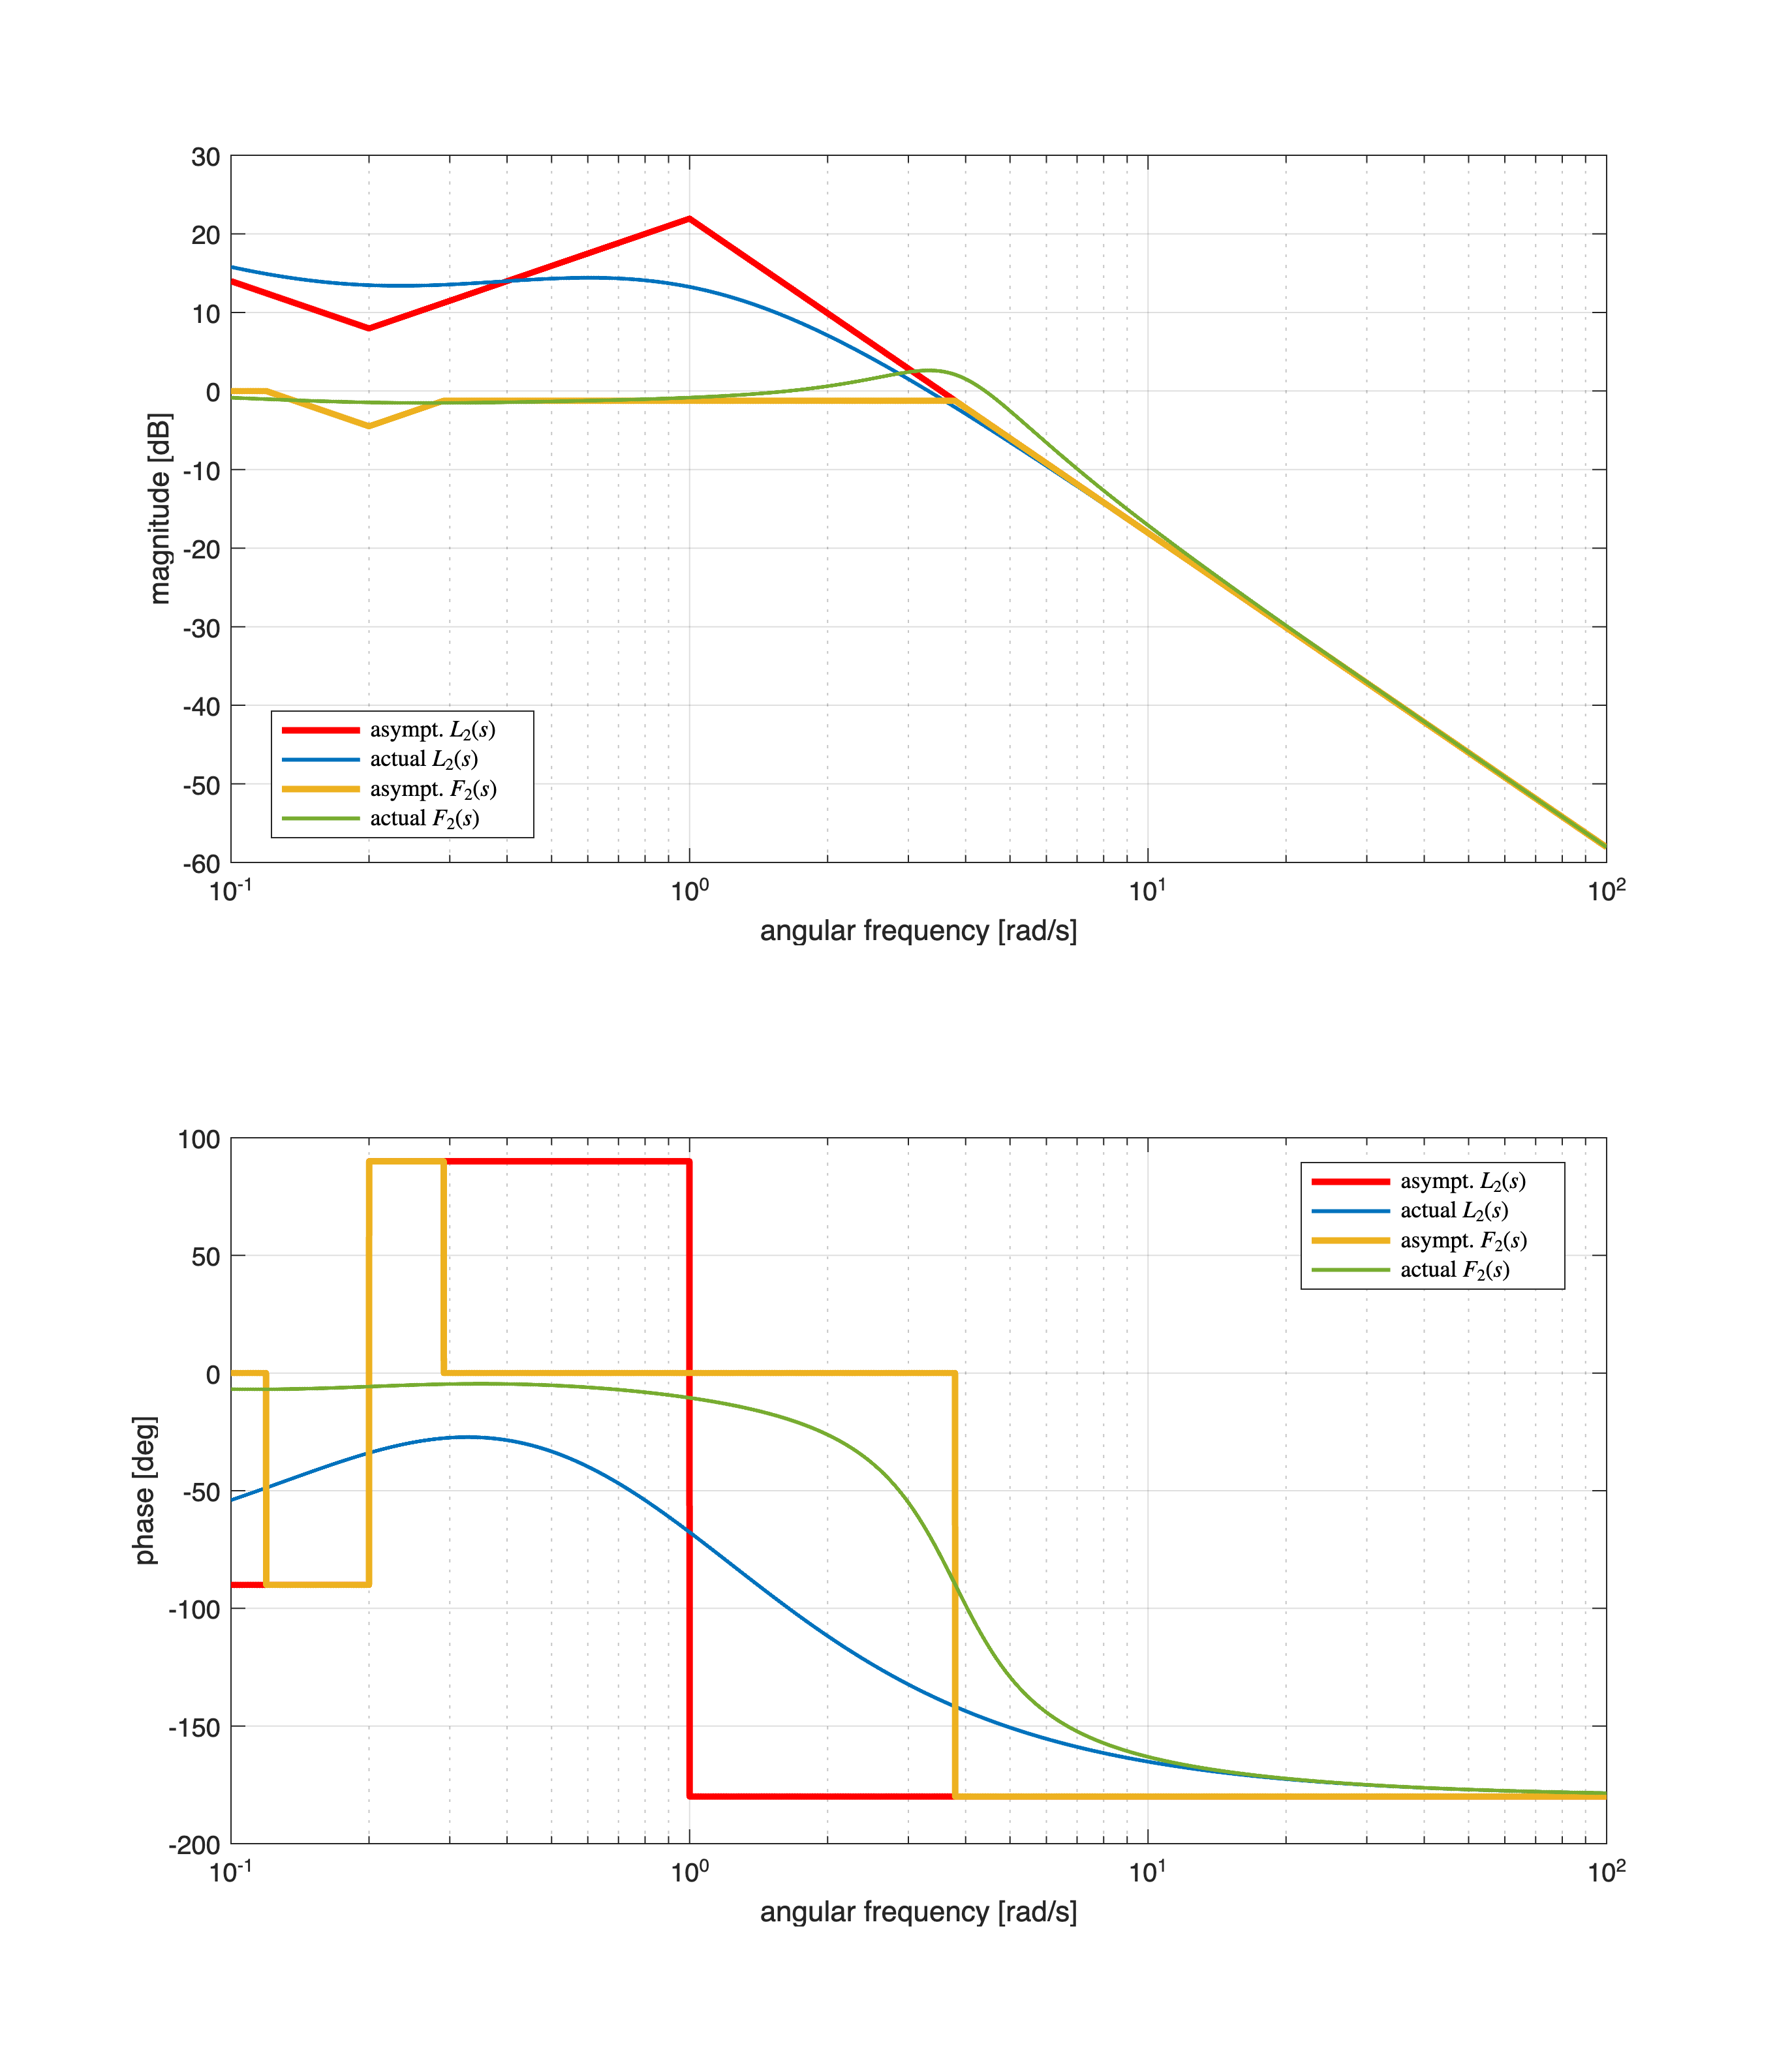


hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams



drawBodediagrams(L2s, omVALS, asBcolor, 2.5, '-', ...
               Bcolors(1, :), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(F2s, omVALS, Bcolors(2, :), 2.5, '-', ...
               Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L_{2}(s)$', 'actual $L_{2}(s)$', ...
             'asympt. $F_{2}(s)$', 'actual $F_{2}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');
legend(hax2, 'asympt. $L_{2}(s)$', 'actual $L_{2}(s)$', ...
             'asympt. $F_{2}(s)$', 'actual $F_{2}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');

[Gm3, Pm3, OMpi3, OMc3] = margin(L3s);
fprintf(['*** Transfer function L3s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n', ...
         'Ang. freq. OMpi [rad/s]: %.4f \n\r', ...
         'Phase margin [deg]: %.4f \r\n',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L3s ***\n\r'], ...
         Gm3, OMpi3, Pm3, OMc3);

*** Transfer function L3s ***


Gain Margin [dB]: 30.8747 
Ang. freq. OMpi [rad/s]: 17.3976 

Phase margin [deg]: 55.2790 
Crit. Ang. freq. OMc [rad/s]: 2.9073 


*** Transfer function L3s ***



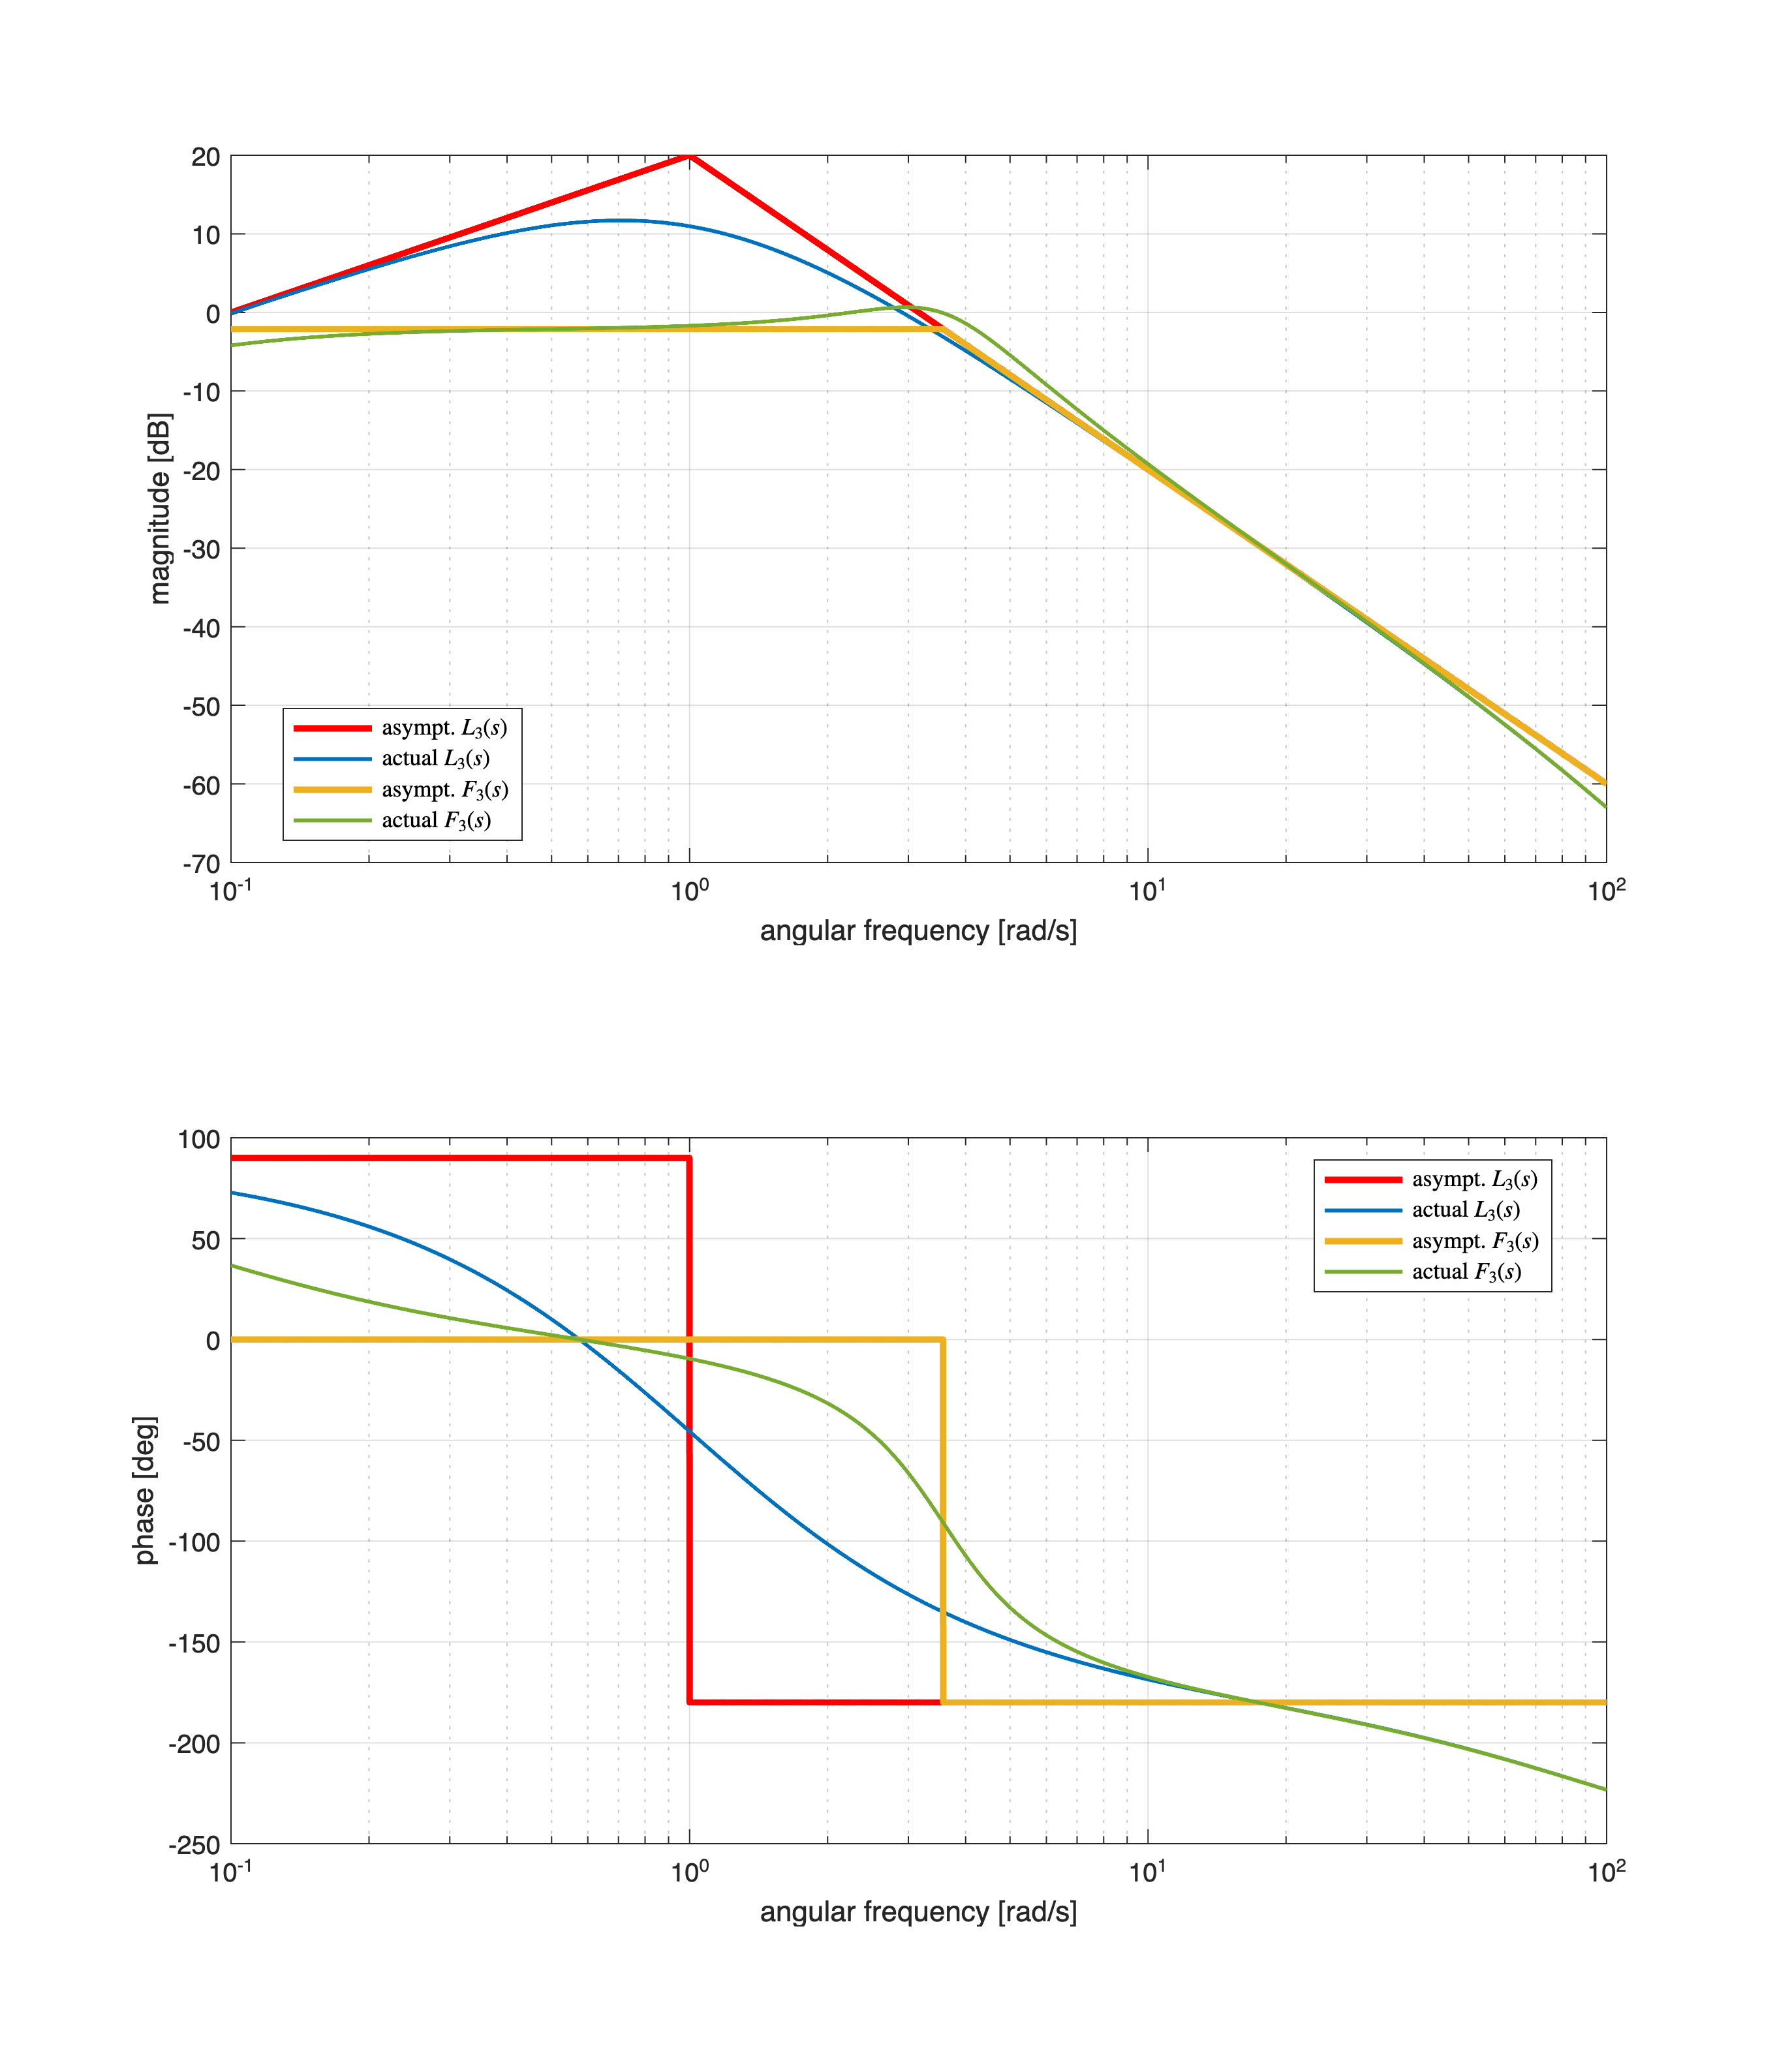



hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams



drawBodediagrams(L3s, omVALS, asBcolor, 2.5, '-', ...
               Bcolors(1, :), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(F3s, omVALS, Bcolors(2, :), 2.5, '-', ...
               Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L_{3}(s)$', 'actual $L_{3}(s)$', ...
             'asympt. $F_{3}(s)$', 'actual $F_{3}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');
legend(hax2, 'asympt. $L_{3}(s)$', 'actual $L_{3}(s)$', ...
             'asympt. $F_{3}(s)$', 'actual $F_{3}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');

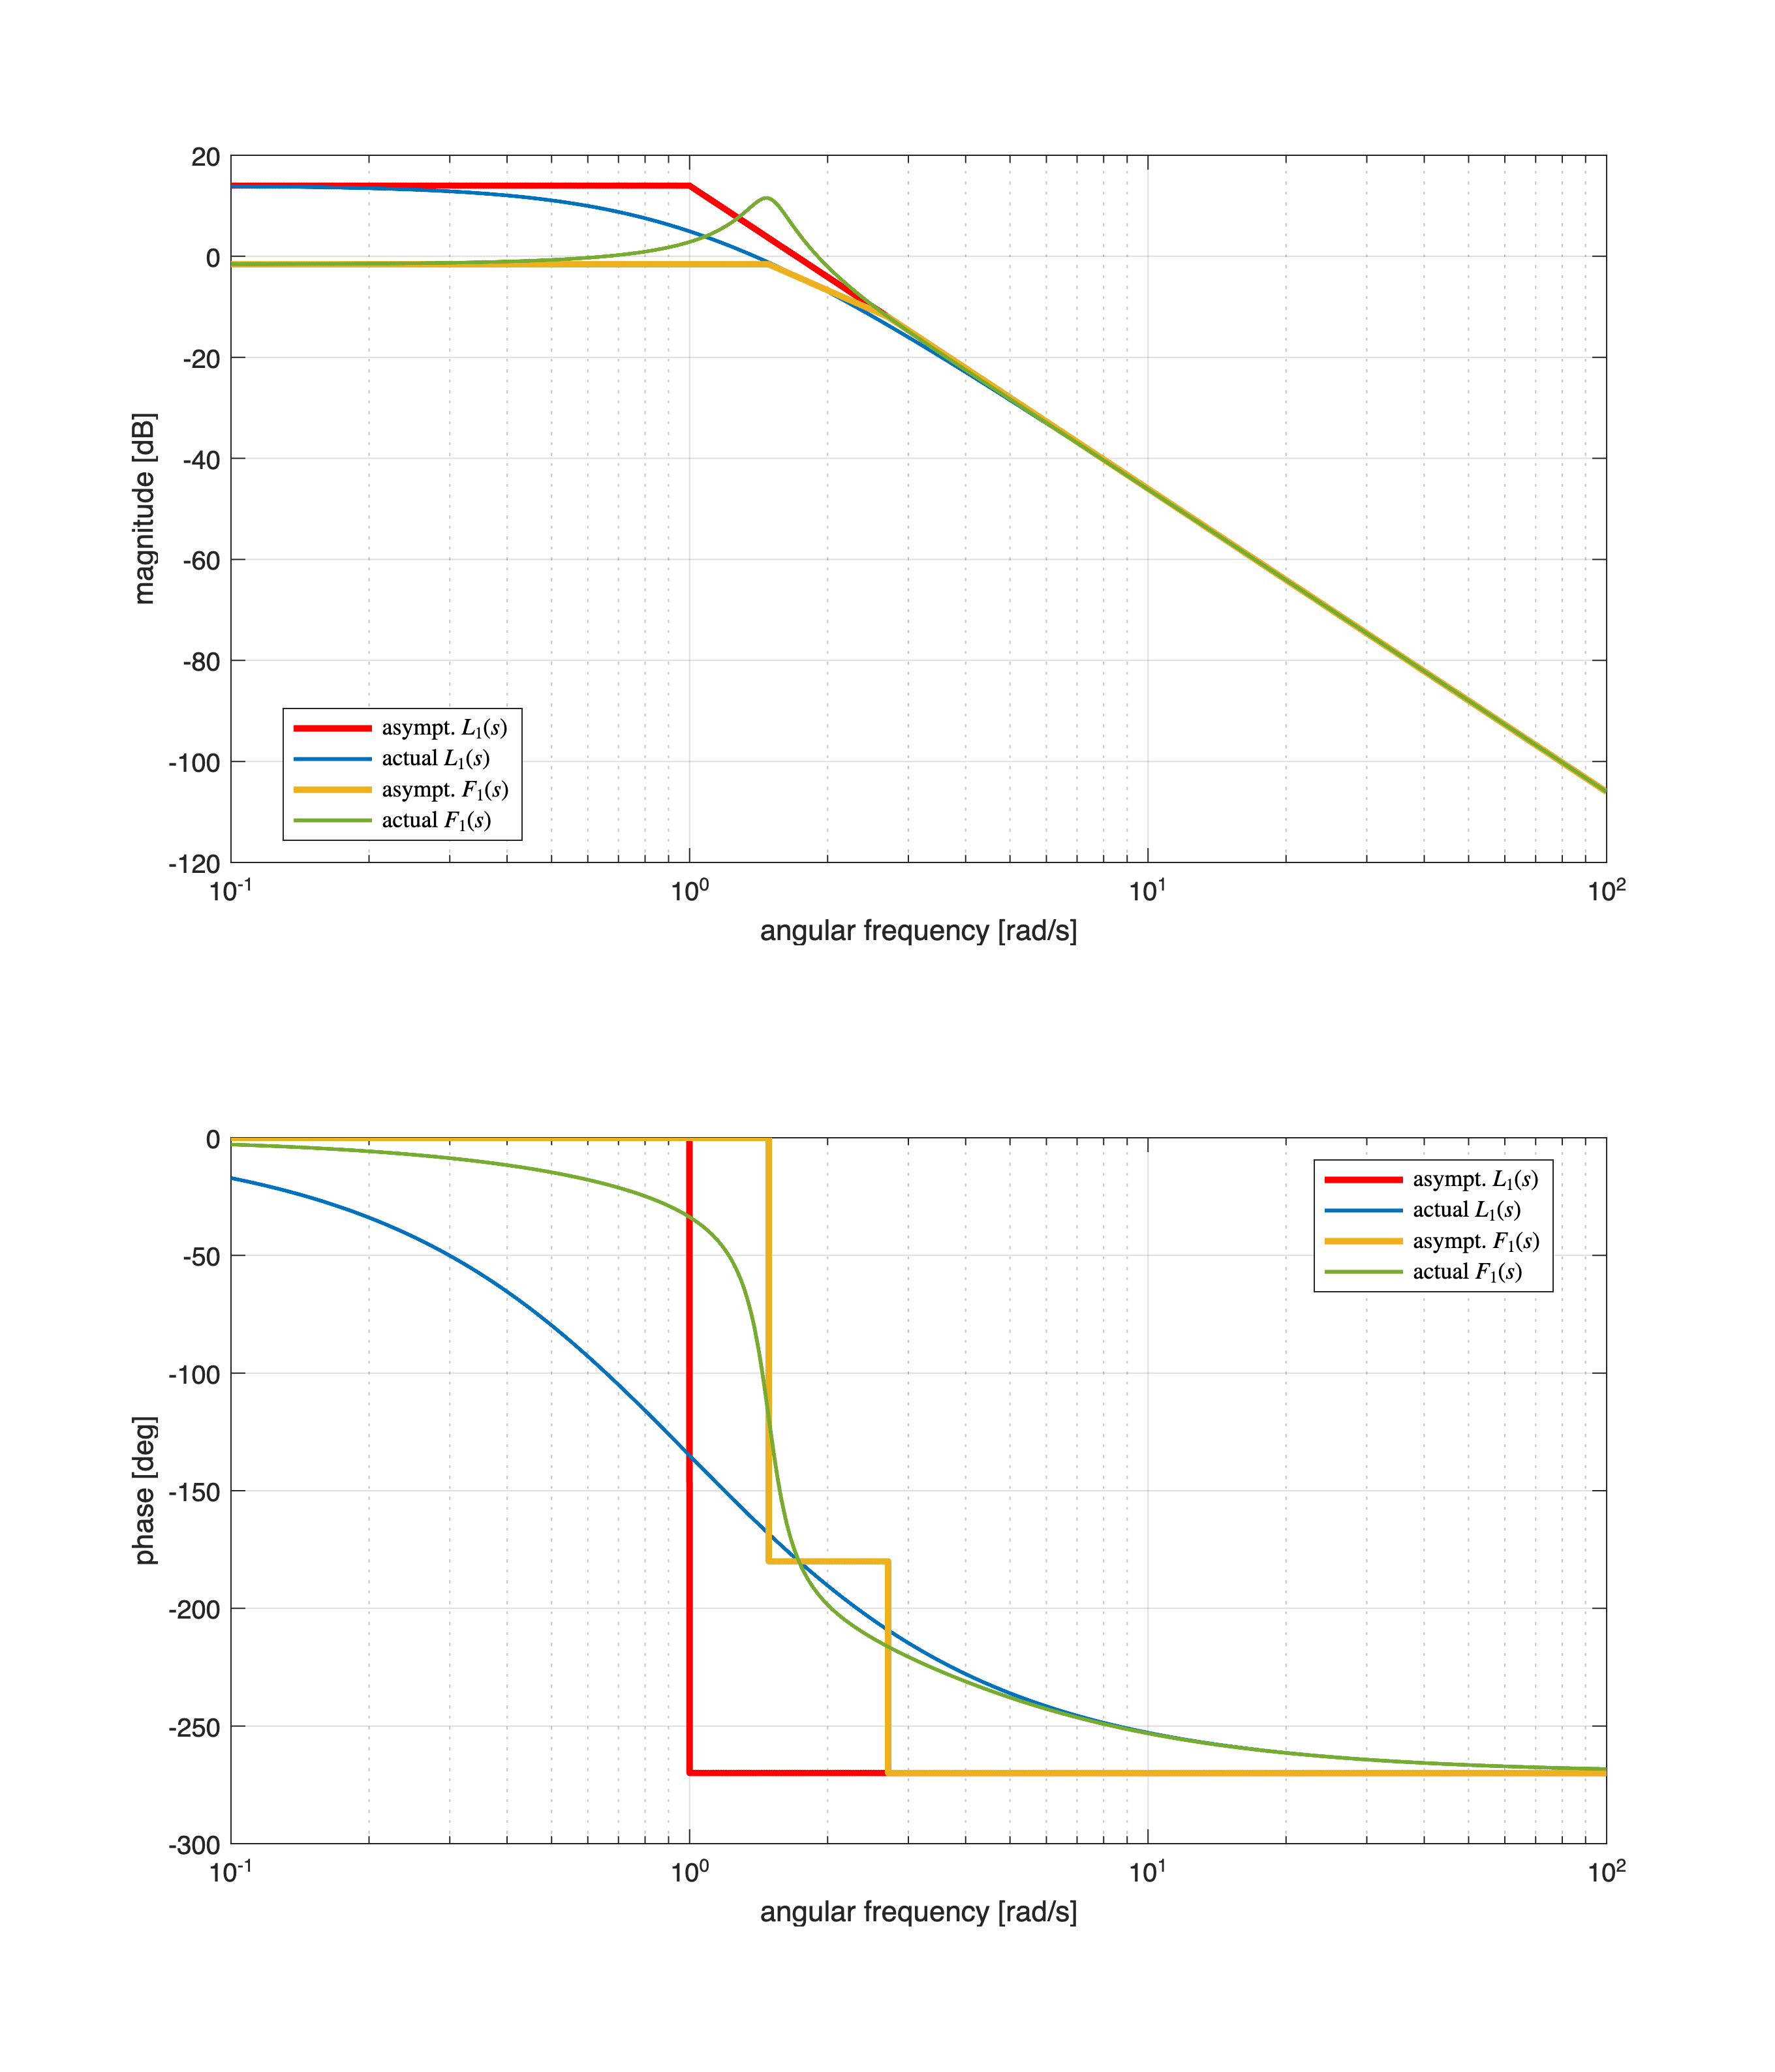

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams



drawBodediagrams(L1s, omVALS, asBcolor, 2.5, '-', ...
               Bcolors(1, :), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(F1s, omVALS, Bcolors(2, :), 2.5, '-', ...
               Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L_{1}(s)$', 'actual $L_{1}(s)$', ...
             'asympt. $F_{1}(s)$', 'actual $F_{1}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');
legend(hax2, 'asympt. $L_{1}(s)$', 'actual $L_{1}(s)$', ...
             'asympt. $F_{1}(s)$', 'actual $F_{1}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');

## The Sensitivity Function

[Gm1, Pm1, OMpi1, OMc1] = margin(L1s);
fprintf(['*** Transfer function L1s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n\r', ...
         'Ang. freq. OMpi [rad/s]: %.4f \r\n', ...
         'Phase margin [deg]: %.4f \n\r',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L1s ***\n\r'], ...
         Gm1, OMpi1, Pm1, OMc1);

*** Transfer function L1s ***


Gain Margin [dB]: 1.6002 

Ang. freq. OMpi [rad/s]: 1.7322 
Phase margin [deg]: 17.3704 

Crit. Ang. freq. OMc [rad/s]: 1.3870 


*** Transfer function L1s ***




S1s = tf(1)-F1s


S1s =
 
  s^3 + 3 s^2 + 3 s + 1
  ---------------------
  s^3 + 3 s^2 + 3 s + 6
 
Continuous-time transfer function.
Model Properties


zpk(S1s)


ans =
 
             (s+1)^3
  ------------------------------
  (s+2.71) (s^2 + 0.29s + 2.214)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(S1s)

ans =   -2.7100 + 0.0000i
  -0.1450 + 1.4809i
  -0.1450 - 1.4809i


zero(S1s)

ans =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i


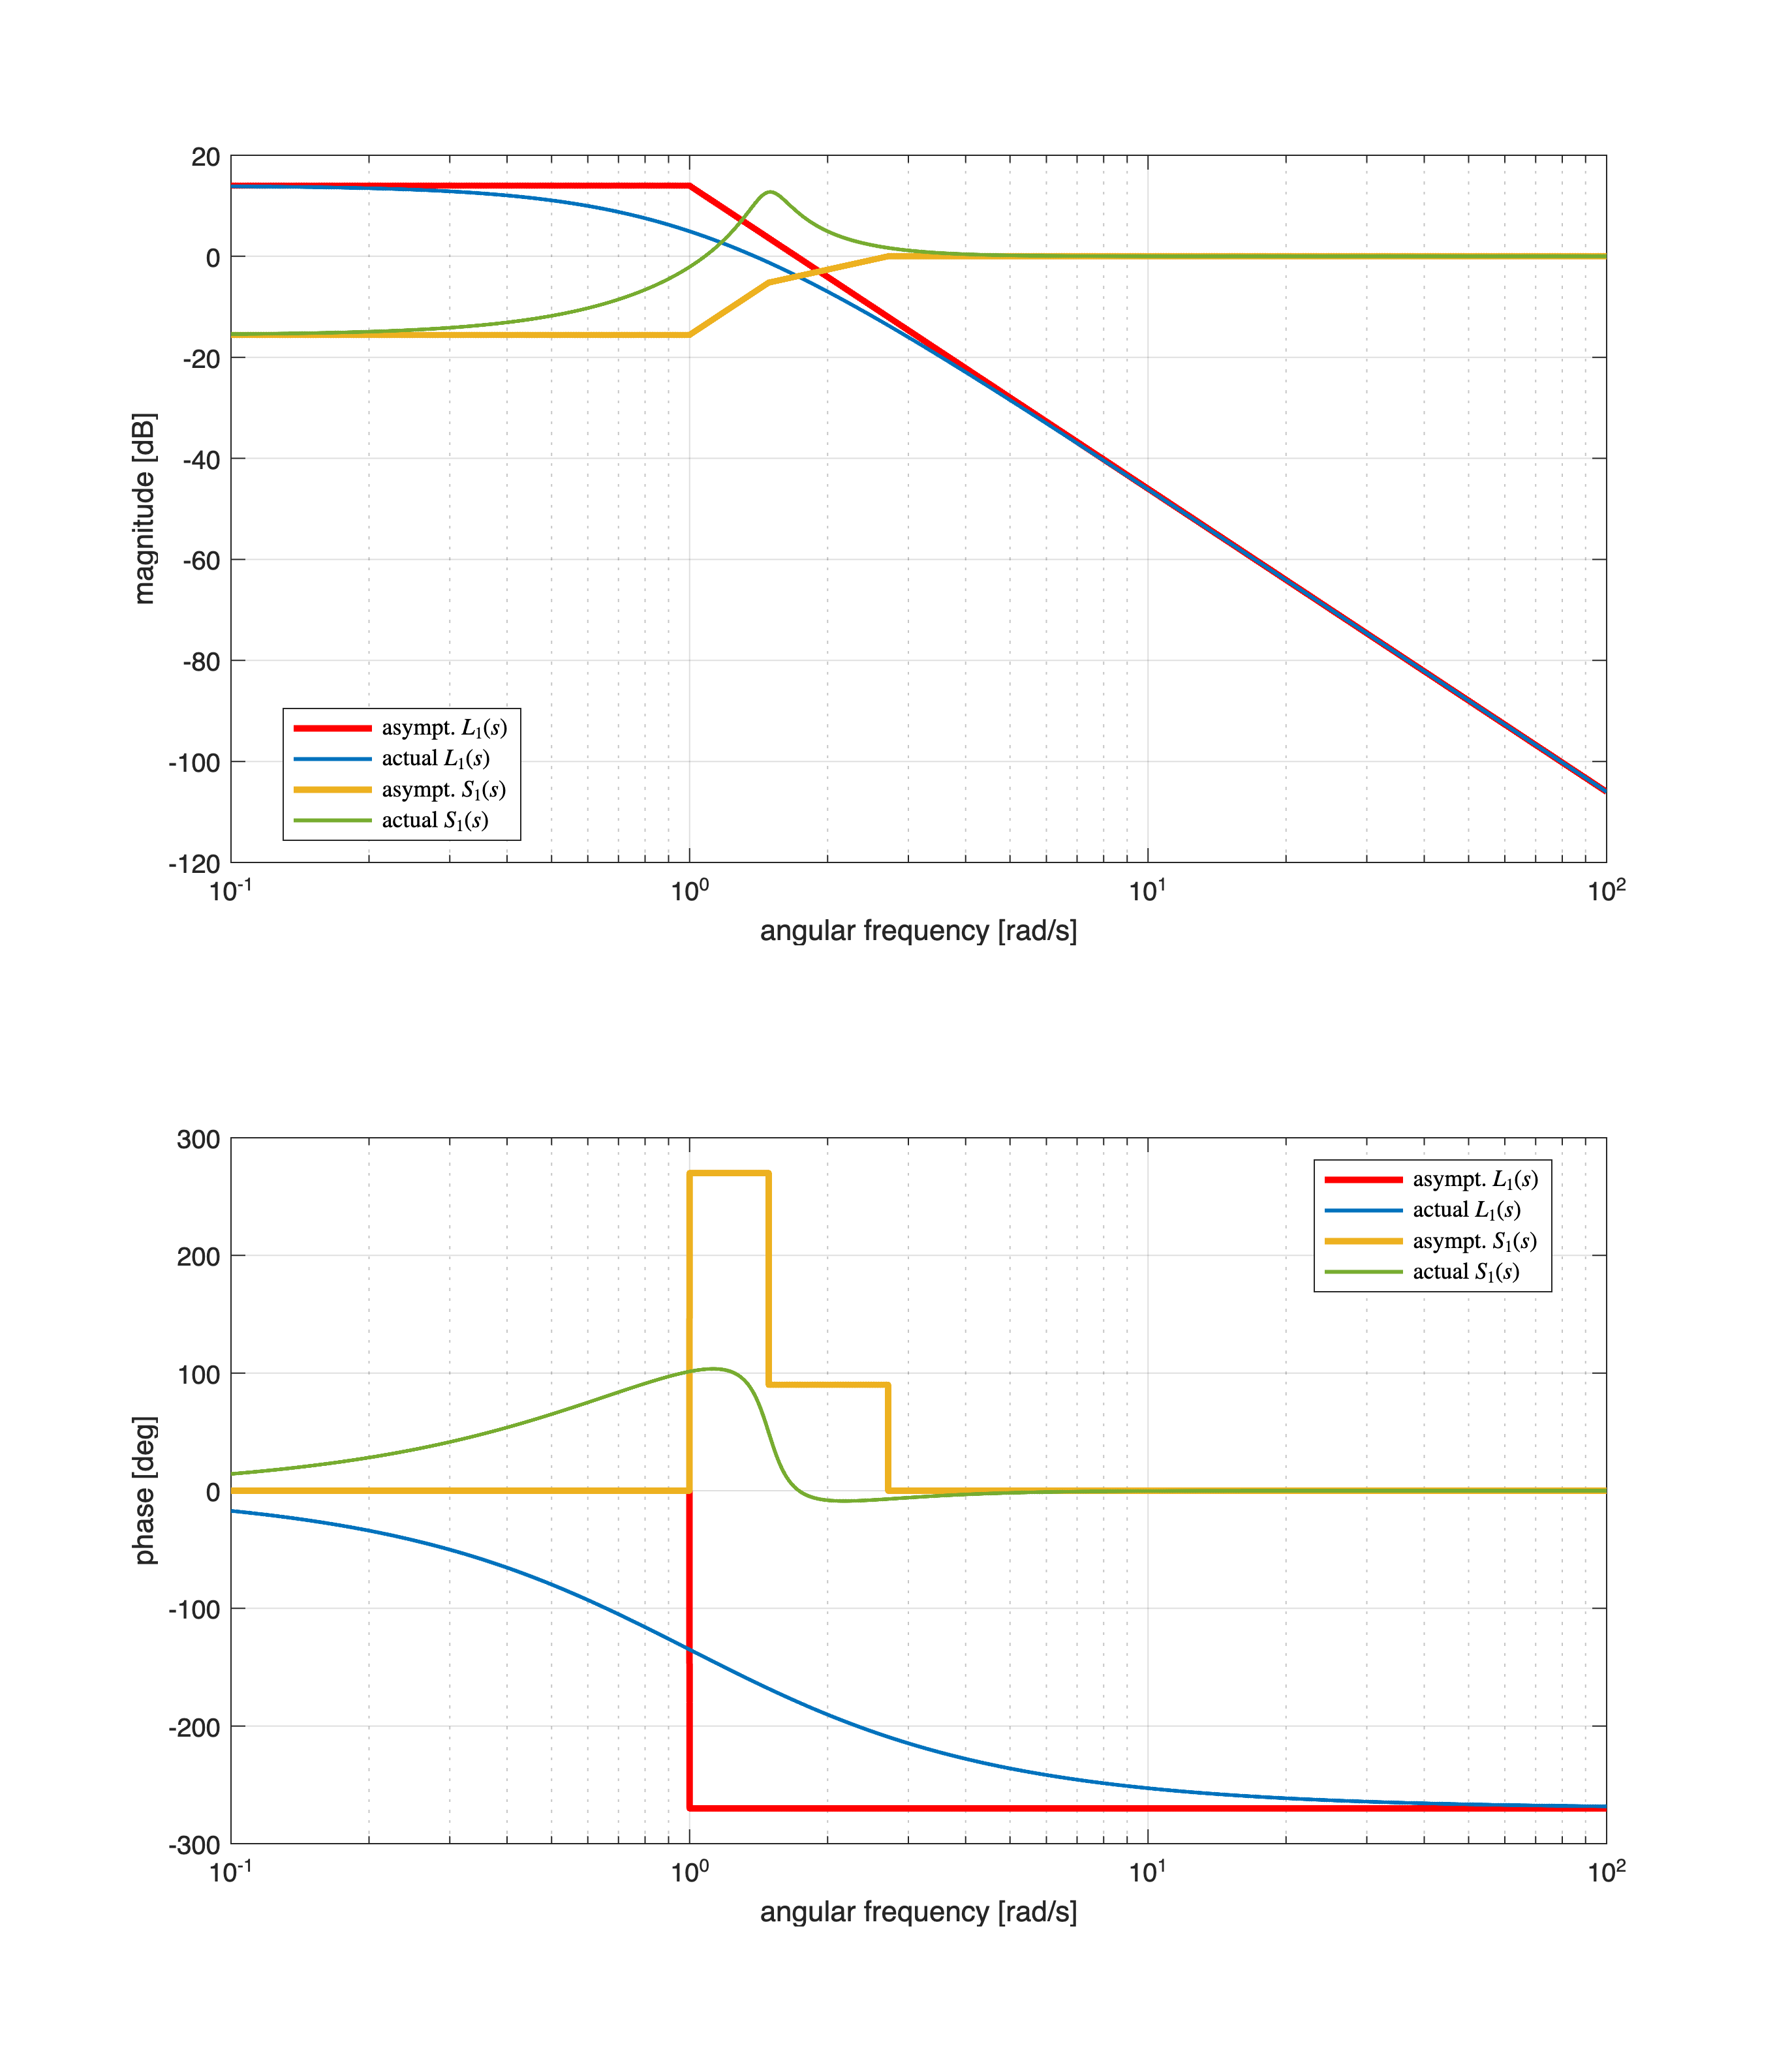



hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams



drawBodediagrams(L1s, omVALS, asBcolor, 2.5, '-', ...
               Bcolors(1, :), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(S1s, omVALS, Bcolors(2, :), 2.5, '-', ...
               Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L_{1}(s)$', 'actual $L_{1}(s)$', ...
             'asympt. $S_{1}(s)$', 'actual $S_{1}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');
legend(hax2, 'asympt. $L_{1}(s)$', 'actual $L_{1}(s)$', ...
             'asympt. $S_{1}(s)$', 'actual $S_{1}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');

[Gm2, Pm2, OMpi2, OMc2] = margin(L2s);
fprintf(['*** Transfer function L1s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n\r', ...
         'Ang. freq. OMpi [rad/s]: %.4f \r\n', ...
         'Phase margin [deg]: %.4f \n\r',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L1s ***\n\r'], ...
         Gm2, OMpi2, Pm2, OMc2);

*** Transfer function L1s ***


Gain Margin [dB]: Inf 

Ang. freq. OMpi [rad/s]: Inf 
Phase margin [deg]: 43.4166 

Crit. Ang. freq. OMc [rad/s]: 3.3181 


*** Transfer function L1s ***




S2s = tf(1)-F2s


S2s =
 
       s^4 + 3 s^3 + 3 s^2 + s
  ----------------------------------
  s^4 + 3 s^3 + 15.5 s^2 + 6 s + 0.5
 
Continuous-time transfer function.
Model Properties


zpk(S2s)


ans =
 
                  s (s+1)^3
  ------------------------------------------
  (s+0.2911) (s+0.1193) (s^2 + 2.59s + 14.4)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(S2s)

ans =   -1.2948 + 3.5674i
  -1.2948 - 3.5674i
  -0.2911 + 0.0000i
  -0.1193 + 0.0000i


zero(S2s)

ans =    0.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i


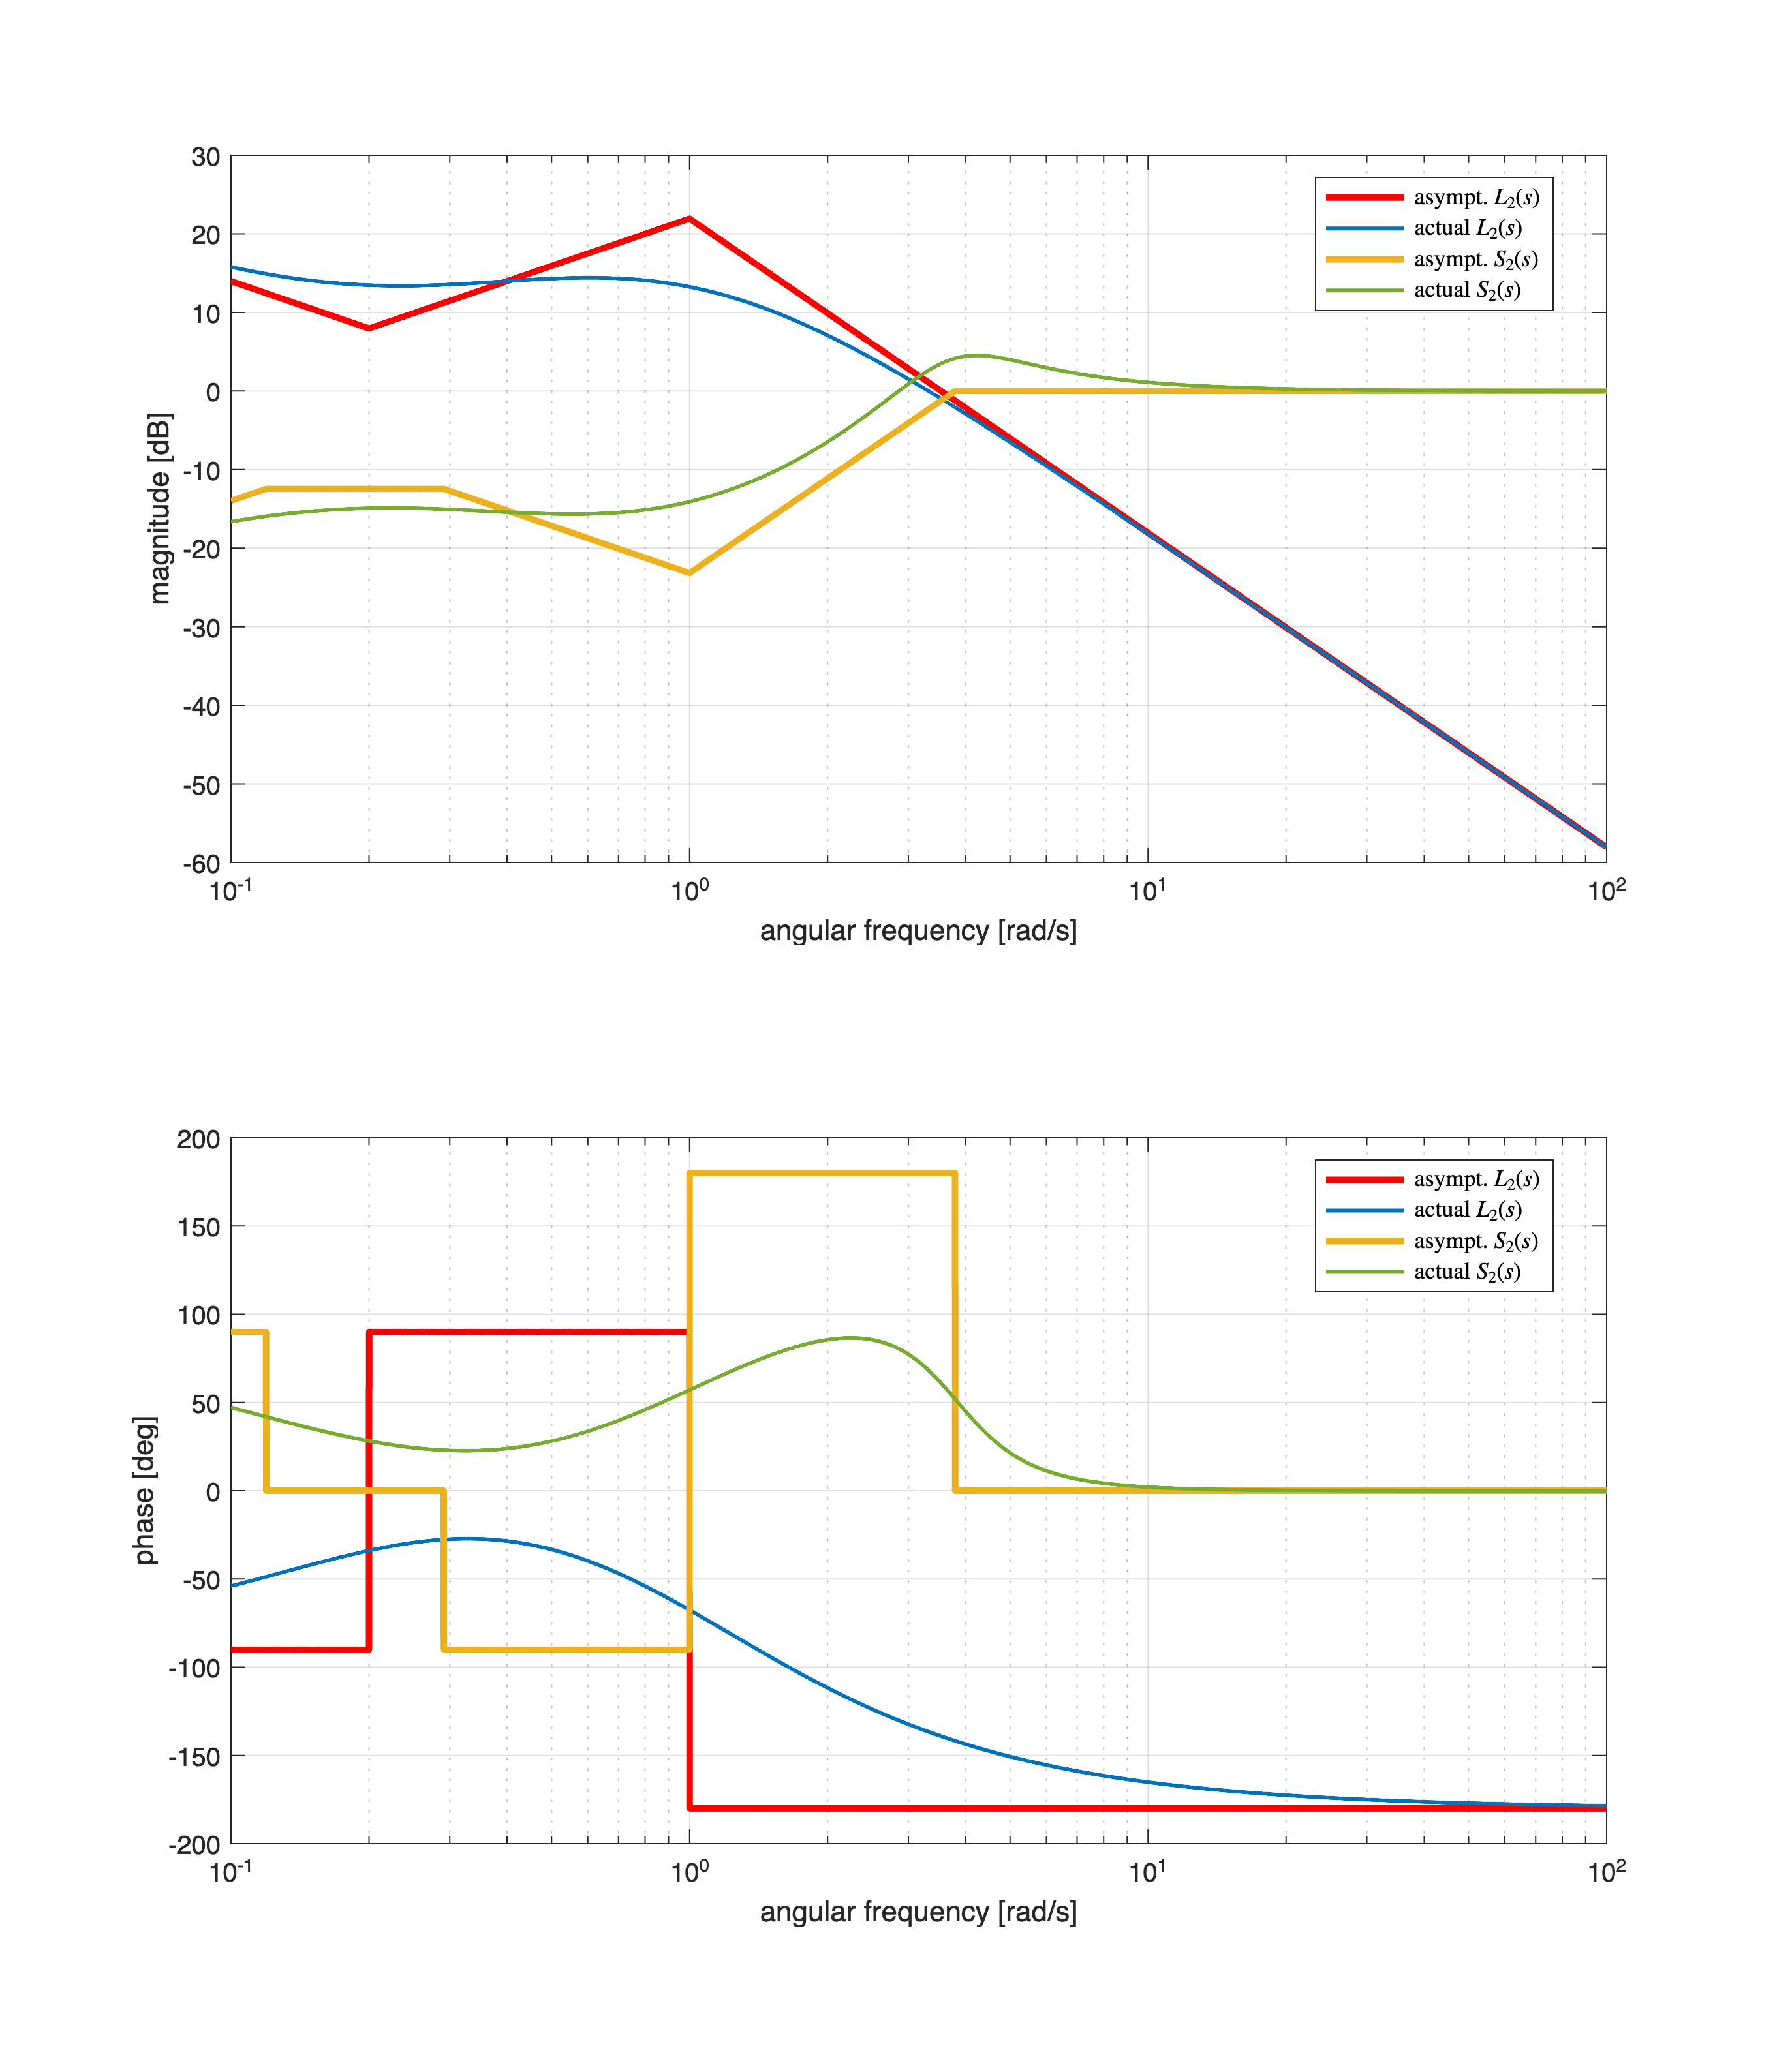



hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams



drawBodediagrams(L2s, omVALS, asBcolor, 2.5, '-', ...
               Bcolors(1, :), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(S2s, omVALS, Bcolors(2, :), 2.5, '-', ...
               Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L_{2}(s)$', 'actual $L_{2}(s)$', ...
             'asympt. $S_{2}(s)$', 'actual $S_{2}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');
legend(hax2, 'asympt. $L_{2}(s)$', 'actual $L_{2}(s)$', ...
             'asympt. $S_{2}(s)$', 'actual $S_{2}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');

[Gm3, Pm3, OMpi3, OMc3] = margin(L3s);
fprintf(['*** Transfer function L1s ***\n\r\n\r' ...
         'Gain Margin [dB]: %.4f \n\r', ...
         'Ang. freq. OMpi [rad/s]: %.4f \r\n', ...
         'Phase margin [deg]: %.4f \n\r',...
         'Crit. Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function L1s ***\n\r'], ...
         Gm3, OMpi3, Pm3, OMc3);

*** Transfer function L1s ***


Gain Margin [dB]: 30.8747 

Ang. freq. OMpi [rad/s]: 17.3976 
Phase margin [deg]: 55.2790 

Crit. Ang. freq. OMc [rad/s]: 2.9073 


*** Transfer function L1s ***




S3s = tf(1)-F3s


S3s =
 
  s^4 + 103 s^3 + 303 s^2 + 301 s + 100
  --------------------------------------
  s^4 + 103 s^3 + 303 s^2 + 1301 s + 100
 
Continuous-time transfer function.
Model Properties


zpk(S3s)


ans =
 
                (s+100) (s+1)^3
  --------------------------------------------
  (s+100.1) (s+0.07825) (s^2 + 2.819s + 12.77)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(S3s)

ans = 1.0e+02 *

  -1.0010 + 0.0000i
  -0.0141 + 0.0328i
  -0.0141 - 0.0328i
  -0.0008 + 0.0000i


zero(S3s)

ans = 1.0e+02 *

  -1.0000 + 0.0000i
  -0.0100 + 0.0000i
  -0.0100 + 0.0000i
  -0.0100 - 0.0000i


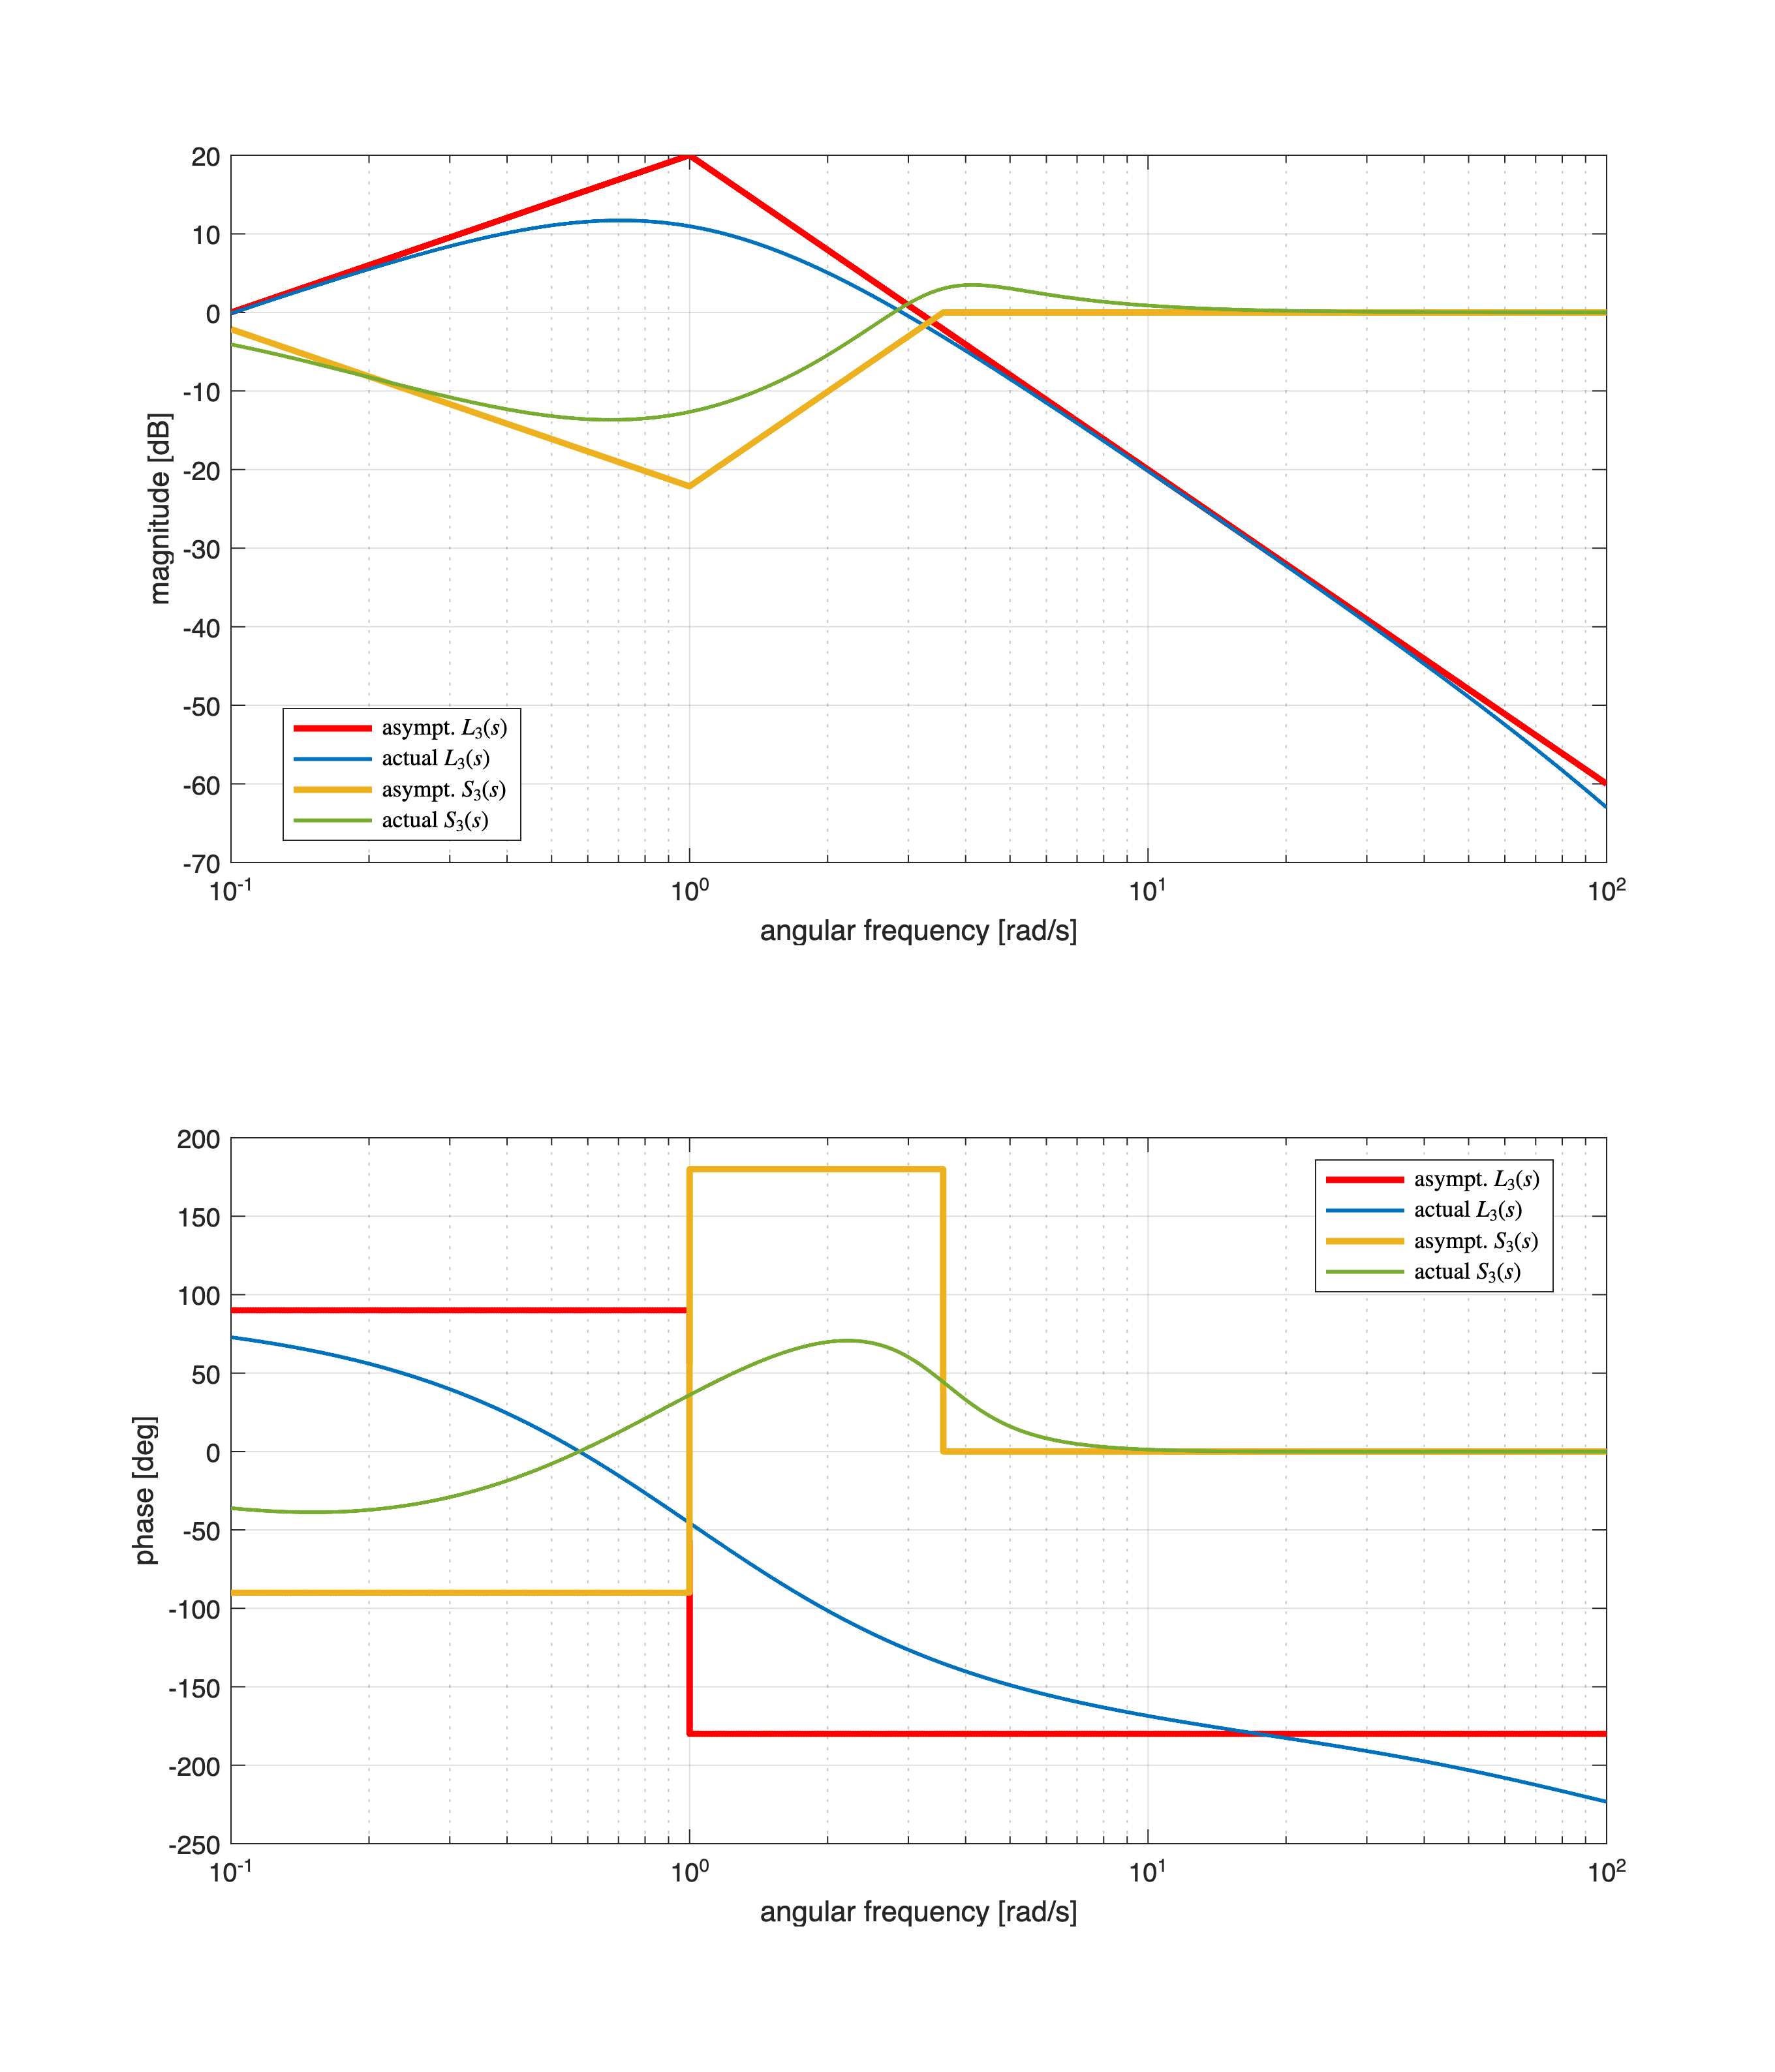



hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams



drawBodediagrams(L3s, omVALS, asBcolor, 2.5, '-', ...
               Bcolors(1, :), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(S3s, omVALS, Bcolors(2, :), 2.5, '-', ...
               Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L_{3}(s)$', 'actual $L_{3}(s)$', ...
             'asympt. $S_{3}(s)$', 'actual $S_{3}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');
legend(hax2,  'asympt. $L_{3}(s)$', 'actual $L_{3}(s)$', ...
             'asympt. $S_{3}(s)$', 'actual $S_{3}(s)$', ...
             'Location', 'best', 'Interpreter', 'latex');